# Final Project

**Japnit Singh Sethi**

clc
clear all
pause('off')
close all

# LQR(Linear-Quadratic Regulator) Design

Our  Open Loop State Space Model with numeric A,B,C and D looks like:

$\left\lbrack \begin{array}{c}
\dot{u} \\
\dot{\;w} \\
\dot{\;q} \\
\dot{x} \\
\dot{\;z} \\
\dot{\;\theta } 
\end{array}\right\rbrack$= $\left\lbrack \begin{array}{cccccc}
-0\ldotp 1819 & 0 & 0 & 0 & 0 & 0\\
0 & -0\ldotp 8422 & -1\ldotp 6830 & 0 & 0 & 0\\
0 & -0\ldotp 2725 & -0\ldotp 9656 & 0 & 0 & 0\\
1 & 0 & 0 & 0 & 0 & 0\\
0 & 1 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\\
w\\
q\\
x\\
z\\
\theta 
\end{array}\right\rbrack$ + $\left\lbrack \begin{array}{ccc}
0\ldotp 0019 & 0 & 0\\
0 & 0\ldotp 0015 & 0\ldotp 0022\\
0 & 0\ldotp 0076 & -0\ldotp 0077\\
0 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$ $\left\lbrack \begin{array}{c}
X_T \\
Z_s \\
Z_b 
\end{array}\right\rbrack$

Rate of Change of State Vector  = A_Numeric * State Vector + B_Numeric * Input Vector

$\left\lbrack \begin{array}{c}
x\\
z\\
\theta 
\end{array}\right\rbrack$= $\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\\
w\\
q\\
x\\
z\\
\theta 
\end{array}\right\rbrack$ + $\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
X_T \\
Z_s \\
Z_b 
\end{array}\right\rbrack$

Output Vector = C * State Vector + D * Input Vector

The LQR function requires a state weighing matrix **Q** and an actuator weighing matrix **R**.

State weighing matrix **Q**:

In order to design the State weighing matrix Q, we will use the "output weighing"

Let $\overset{\cdot }{Q}$ be the output weighing matrix, the we can calculate Q as:

Q = $C_{\mathrm{OL}}^T *\overset{\cdot }{Q} *C_{\mathrm{OL}} \;$, where $C_{\mathrm{OL}} \;$ is the C matrix of the Open-loop system and $C_{\mathrm{OL}}^T$ is it's transpose

**Note**: Varying the weighting matrices **Q** and **R** allows us to trade off the "size" of the state response with the size of the control effort. For example,

If $\left|Q\right|$ <<$\left|R\right|$, then cost function will minimize the amount of control effort needed (i.e. gains will be small).

If $\left|Q\right|$ >>$\left|R\right|$, then cost function will minimize the state response without regard to amount of control effort needed (i.e. gains will be large).

**Note**: Q is technically going to be a diagonal matrix, with each diagonal element corresponding to a specific state, so for example we want state element 1 to have the least error then we can make the diagonal element from the Q  matrix corresponding to state element 1 larger than others to do so.

R is similar to Q but acts on the input vector.

% Problem 1a.

% Initial condition for output responses
x_0 = -463 + 50;            % meters
z_0 = -150 + 350;           % meters
theta_0 = (45*pi/180);      % 45 degrees = (45*pi/180) radians

% Initial condition for State Variables
u_0 = 100;          % m/s
w_0 = -300;         % m/s
q_0 = 0;            % rad/s

State_Variable_Vector_0 = [u_0; w_0; q_0; x_0; z_0; theta_0];

% Importing the Open-Loop system from the file "Midterm_OL_SS_LTI_Model.mat"
load('Midterm_OL_SS_LTI_Model.mat','ol_sys');

% Extracting the Open-Loop A, B, C, and D matrices from the OL system 
A_ol = ol_sys.A; 
B_ol = ol_sys.B; 
C_ol = ol_sys.C; 
D_ol = ol_sys.D; 

% Let's assume our Q_star (output weighing matrix) to be:
Q_star = 10e6* [8.5, 0, 0;...
                0, 3.8, 0;... 
                0, 0, 13];
  
% Therefore, Our Q (State wighing matrix) is:
Q = C_ol' * Q_star * C_ol;
R = diag([1.5 0.1 0.05]);
[K_lqr,S_lqr,P_lqr] = lqr(ol_sys,Q,R);
% where K is my state feedback gain matrix, S is the Riccati solution and P
% are the closed loop eigen values

# Initial Value Response (LQR)

## **Performance requirements:**

- $\left|X_T \right|\le U_{\mathrm{max}\;}$          where   $U_{\mathrm{max}\;}$ = 3000000 N or 3e6 N

- 
$$\left|Z_s \right|\le U_{\mathrm{max}\;}$$


- 
$$\left|Z_b \right|\le U_{\mathrm{max}\;}$$


- Also Each of the above states input control signals must have their maximum value within 10% of the peak limit i.e  $3\mathrm{e5}\;\le \;\left|X_T \right|,\left|Z_s \right|,\left|Z_b \right|\le 3\mathrm{e6}$

- AUV must completely enter the tunnel without contacting the barrier

- Minimize the time it takes to enter the tunnel

- 5% Settling time of all three outputs must be less than 1 second.

## **Requirements Passed:**

- 5% Settling times: X - 0.77 seconds, Z - 0.36 seconds , $\theta$ - 0.69 seconds

- Input Control Signal:  $X_T$ - 6e+5, $Z_s$ - 2e+6, $Z_b$ - 2.95e+6

- Time Taken for AUV to Enter the Tunnel: 0.9 seconds

% Problem 1b.

% Simulating initial value response for closed loop system using LQR
% optimal control gains
A_closed = A_ol - B_ol * K_lqr; % equivalent closed-loop A 
% cl_sys = ss(A_closed,[],C_ol,[]); % closed loop sys
cl_sys = ss(A_closed,B_ol,C_ol,D_ol); % closed loop sys
tfinal = 0.9; % time in tfinal seconds for simulation in order to capture the instant my auv enters tunnel and cut off that extra time it goes forward and comes back
[Y_lqr,t_lqr,X_lqr] = initial(cl_sys, State_Variable_Vector_0, tfinal);

disp('Poles to the closed loop system using LQR optimal control gains are: ');

Poles to the closed loop system using LQR optimal control gains are: 


disp(pole(cl_sys));

  -2.7037 + 2.7007i
  -2.7037 - 2.7007i
 -15.4706 +15.4569i
 -15.4706 -15.4569i
  -5.4072 + 5.3274i
  -5.4072 - 5.3274i




% We need to cut those x and z values back for final plot
Y_lqr(:,1) = Y_lqr(:,1) + 463;
Y_lqr(:,2) = Y_lqr(:,2) + 150;

% Converting the theta angle from degrees to radians
Y_lqr(:,3) = (Y_lqr(:,3)*pi/180);
X_lqr(:,6) = (X_lqr(:,6)*pi/180);

% Calculating 5% Settling time for all three outputs of closed loop system
SimulationStuff1 = lsiminfo(Y_lqr(:,1),t_lqr,'SettlingTimeThreshold',0.05);
SimulationStuff2 = lsiminfo(Y_lqr(:,2),t_lqr,'SettlingTimeThreshold',0.05);
SimulationStuff3 = lsiminfo(Y_lqr(:,3),t_lqr,'SettlingTimeThreshold',0.05);

% Position in X (x) at 5% Settling time, 
X_at_SettlingTime = interp1(t_lqr(:,1),Y_lqr(:,1),SimulationStuff1.SettlingTime);


% Depth(z) at 5% Settling time, 
Depth_at_SettlingTime = interp1(t_lqr(:,1),Y_lqr(:,2),SimulationStuff2.SettlingTime);

% Pitch Angle (theta) at 5% Settling time, 
PitchAngle_at_SettlingTime = interp1(t_lqr(:,1),Y_lqr(:,3),SimulationStuff3.SettlingTime);


disp(' ======== Closed-Loop System using LQR Control gains ========= ');

 ======== Closed-Loop System using LQR Control gains ========= 


disp(' ');



% show the settling time for each output: 
T = table({'x in meter'; 'z in meter'; 'theta in rad'}, [X_at_SettlingTime ;Depth_at_SettlingTime; PitchAngle_at_SettlingTime], [SimulationStuff1.SettlingTime; SimulationStuff2.SettlingTime; SimulationStuff3.SettlingTime]);
T.Properties.VariableNames = {'Output_Name','Output_Value','Settling_Time_in_s'};
disp(T);

     Output_Name      Output_Value    Settling_Time_in_s
    ______________    ____________    __________________

    'x in meter'           447.96          0.77389      
    'z in meter'           159.09          0.36082      
    'theta in rad'     -0.0083764          0.69708      




% To find the each control thrust value
% Our Control Objective is to have max of each Control thrust value within
% 10% of Peak limit of 3e6
Thrust = K_lqr*X_lqr'; % magnitudes of ctrl thrust measurement at each timestep

Max_of_Thrust_X_T = max(Thrust(1,:));
Max_of_Stern_Thrust_Z_s = max(Thrust(2,:));
Max_of_Bow_Thrust_Z_b = max(Thrust(3,:));

% worst_control_Thrust = max(max(Thrust));
fprintf(' Max Thrust X_T is: %6.f N or %.1e N ', Max_of_Thrust_X_T, Max_of_Thrust_X_T);

 Max Thrust X_T is: 604377 N or 6.0e+05 N 

fprintf(' Max Stern Thrust Z_s is: %6.f N or %.1e N ', Max_of_Stern_Thrust_Z_s, Max_of_Stern_Thrust_Z_s);

 Max Stern Thrust Z_s is: 2025177 N or 2.0e+06 N 

fprintf(' Max Bow Thrust Z_b is: %6.f N or %.1e N ', Max_of_Bow_Thrust_Z_b, Max_of_Bow_Thrust_Z_b);

 Max Bow Thrust Z_b is: 2946327 N or 2.9e+06 N 

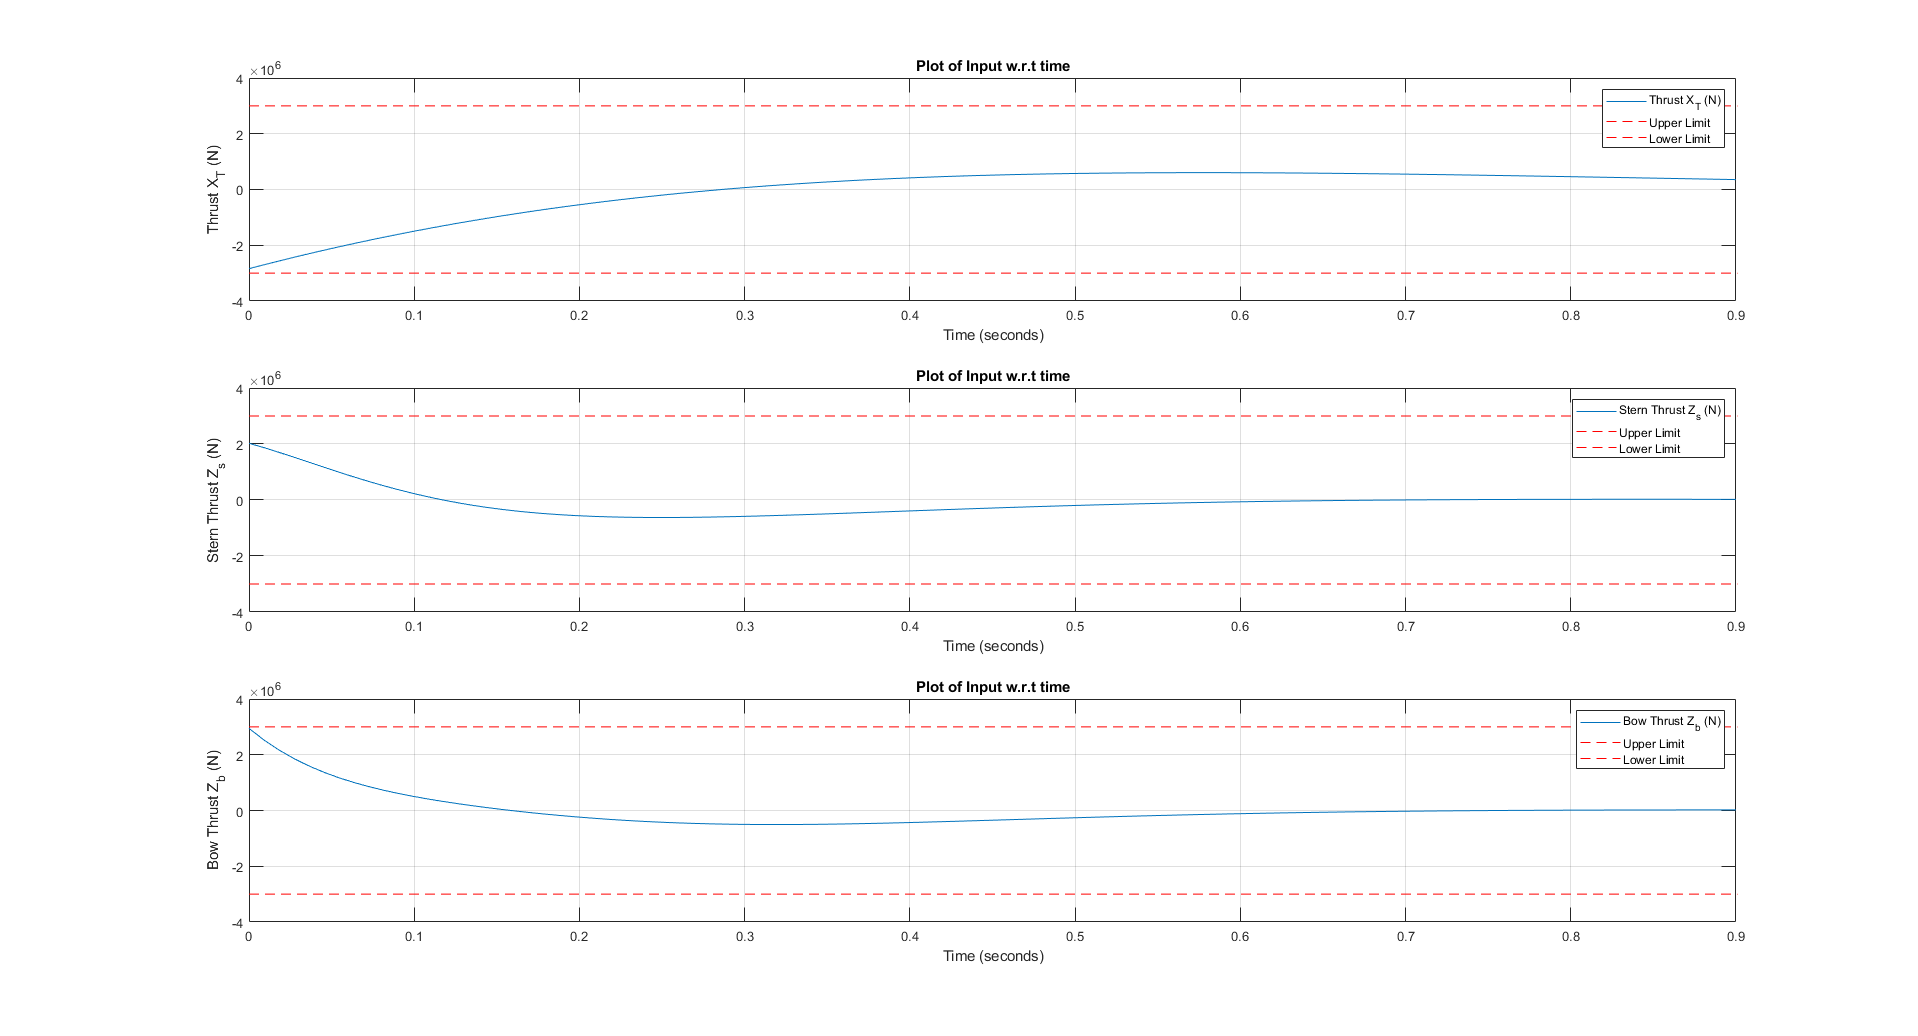



% Plotting Inputs
figure()
subplot(3,1,1)
plot(t_lqr,Thrust(1,:));
grid on
hRefl=refline(0,3e6);
set(hRefl,'color','r','linestyle','--'); % Max horizontal
hRef2=refline(0,-3e6);
set(hRef2,'color','r','linestyle','--'); % Min horizontal
title('Plot of Input w.r.t time');
xlabel('Time (seconds)')
ylabel('Thrust X_T (N)')
legend('Thrust X_T (N)','Upper Limit','Lower Limit');
xlim([0 tfinal]);
ylim([-4e6 4e6]);

subplot(3,1,2)
plot(t_lqr,Thrust(2,:));
grid on
hRefl=refline(0,3e6);
set(hRefl,'color','r','linestyle','--'); % Max horizontal
hRef2=refline(0,-3e6);
set(hRef2,'color','r','linestyle','--'); % Min horizontal
title('Plot of Input w.r.t time');
xlabel('Time (seconds)')
ylabel('Stern Thrust Z_s (N)')
legend('Stern Thrust Z_s (N)','Upper Limit','Lower Limit');
xlim([0 tfinal]);
ylim([-4e6 4e6]);

subplot(3,1,3)
plot(t_lqr,Thrust(3,:));
grid on
hRefl=refline(0,3e6);
set(hRefl,'color','r','linestyle','--'); % Max horizontal
hRef2=refline(0,-3e6);
set(hRef2,'color','r','linestyle','--'); % Min horizontal
title('Plot of Input w.r.t time');
xlabel('Time (seconds)')
ylabel('Bow Thrust Z_b (N)')
legend('Bow Thrust Z_b (N)','Upper Limit','Lower Limit');
xlim([0 tfinal]);
ylim([-4e6 4e6]);

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

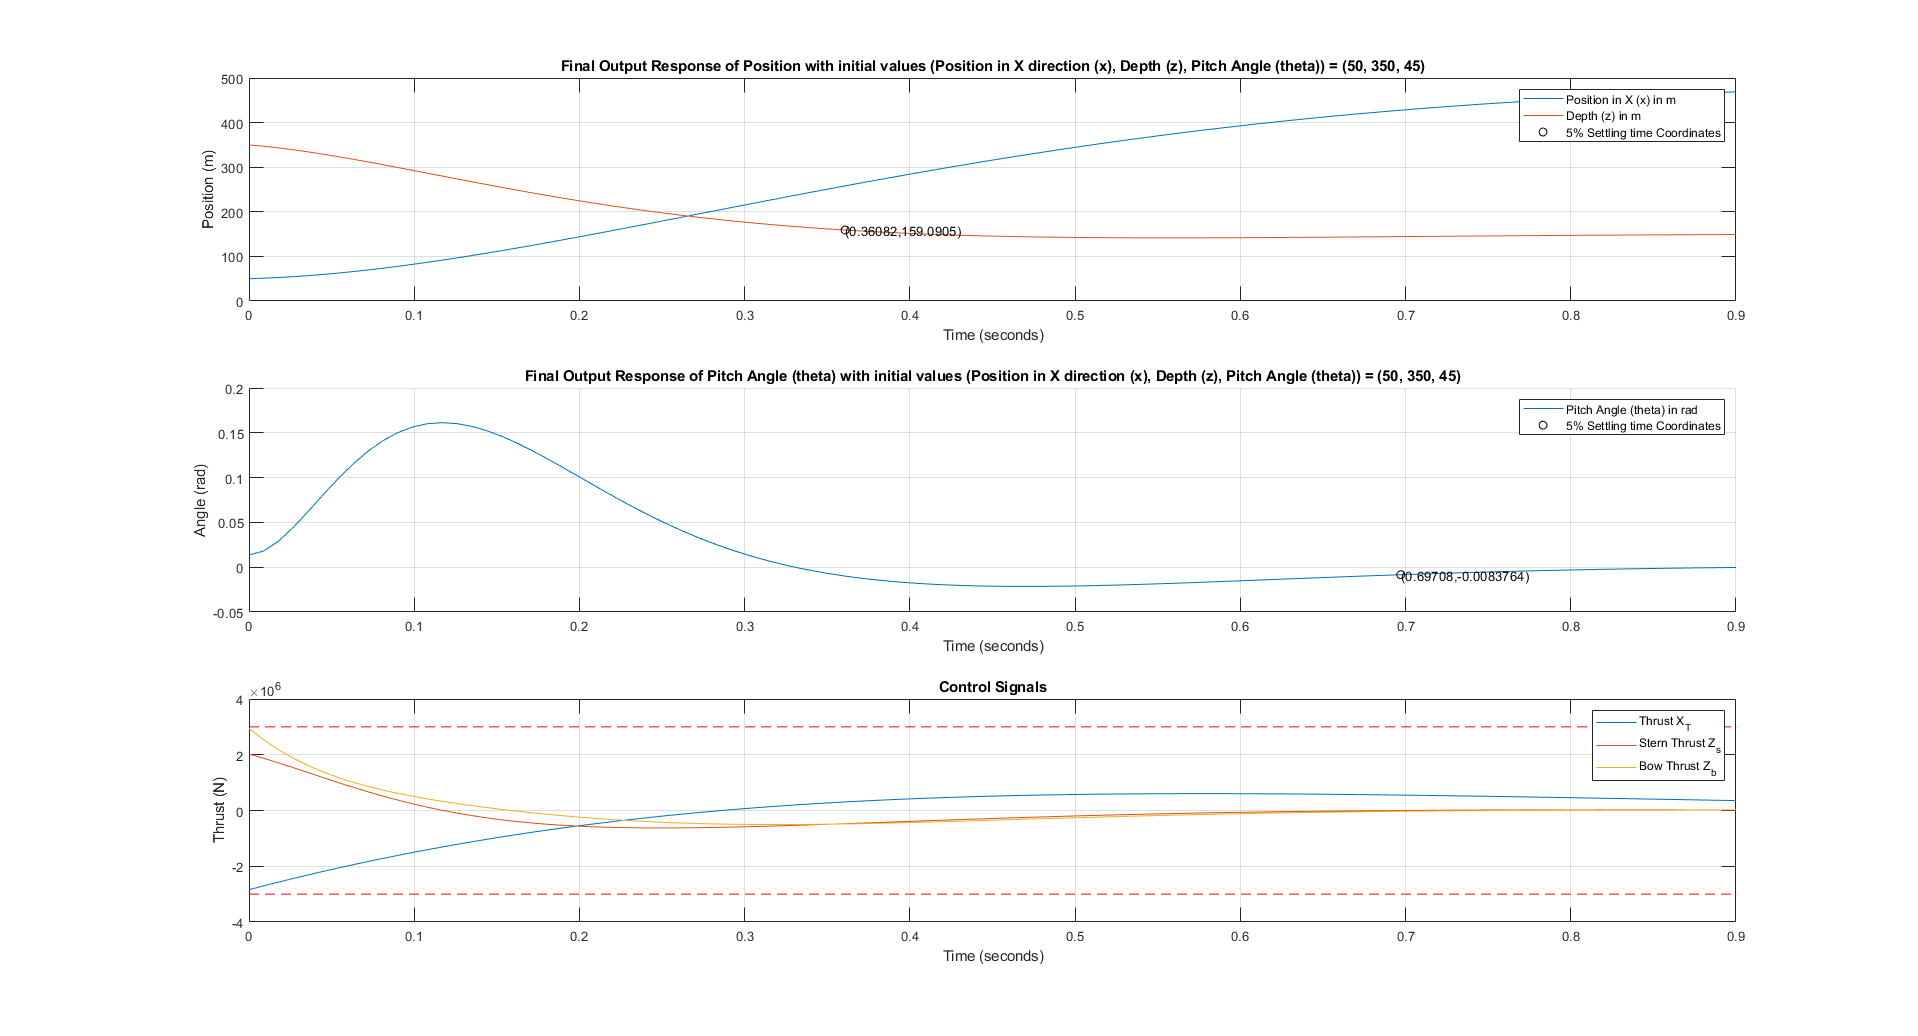


figure()
% Construct the 1st plot of just Positions in m
subplot(3,1,1)
plot(t_lqr,Y_lqr(:,1));
grid on
hold on
plot(t_lqr,Y_lqr(:,2));
title(['Final Output Response of Position with initial values (Position in X direction (x), Depth (z), Pitch Angle (theta))',...
    ' = (50, 350, 45)']);
xlabel('Time (seconds)');
ylabel('Position (m)');
xlim([0 tfinal]);

plot(SimulationStuff1.SettlingTime, X_at_SettlingTime,'kO');
text(SimulationStuff1.SettlingTime, X_at_SettlingTime,['(' num2str(SimulationStuff1.SettlingTime) ',' num2str(X_at_SettlingTime) ')']);

plot(SimulationStuff2.SettlingTime, Depth_at_SettlingTime,'kO');
text(SimulationStuff2.SettlingTime, Depth_at_SettlingTime,['(' num2str(SimulationStuff2.SettlingTime) ',' num2str(Depth_at_SettlingTime) ')']);
legend('Position in X (x) in m', 'Depth (z) in m','5% Settling time Coordinates');
hold off

% Construct the 2nd Plot of just Pitch Angle in rad
subplot(3,1,2)
hold on
grid on
plot(t_lqr,Y_lqr(:,3));
title(['Final Output Response of Pitch Angle (theta) with initial values (Position in X direction (x), Depth (z), Pitch Angle (theta))',...
    ' = (50, 350, 45)']);
xlabel('Time (seconds)')
ylabel('Angle (rad)');

plot(SimulationStuff3.SettlingTime, PitchAngle_at_SettlingTime,'kO');
text(SimulationStuff3.SettlingTime, PitchAngle_at_SettlingTime,['(' num2str(SimulationStuff3.SettlingTime) ',' num2str(PitchAngle_at_SettlingTime) ')']);
legend('Pitch Angle (theta) in rad','5% Settling time Coordinates');
xlim([0 tfinal]);
% ylim([-0.3 1]);
hold off

CtrlThrust = K_lqr*X_lqr'; % inputs U

% Plotting the Control Signals
subplot(3, 1, 3)
plot(t_lqr, CtrlThrust(1,:))
hold on
plot(t_lqr, CtrlThrust(2,:))
plot(t_lqr, CtrlThrust(3,:))
hold off
grid on
hRefl=refline(0,3e6);
set(hRefl,'color','r','linestyle','--'); % Max horizontal
hRef2=refline(0,-3e6);
set(hRef2,'color','r','linestyle','--'); % Min horizontal
legend('Thrust X_T', 'Stern Thrust Z_s', 'Bow Thrust Z_b');
xlabel('Time (seconds)');
ylabel('Thrust (N)');
title('Control Signals');
xlim([0 tfinal]);
ylim([-4e6 4e6]);
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

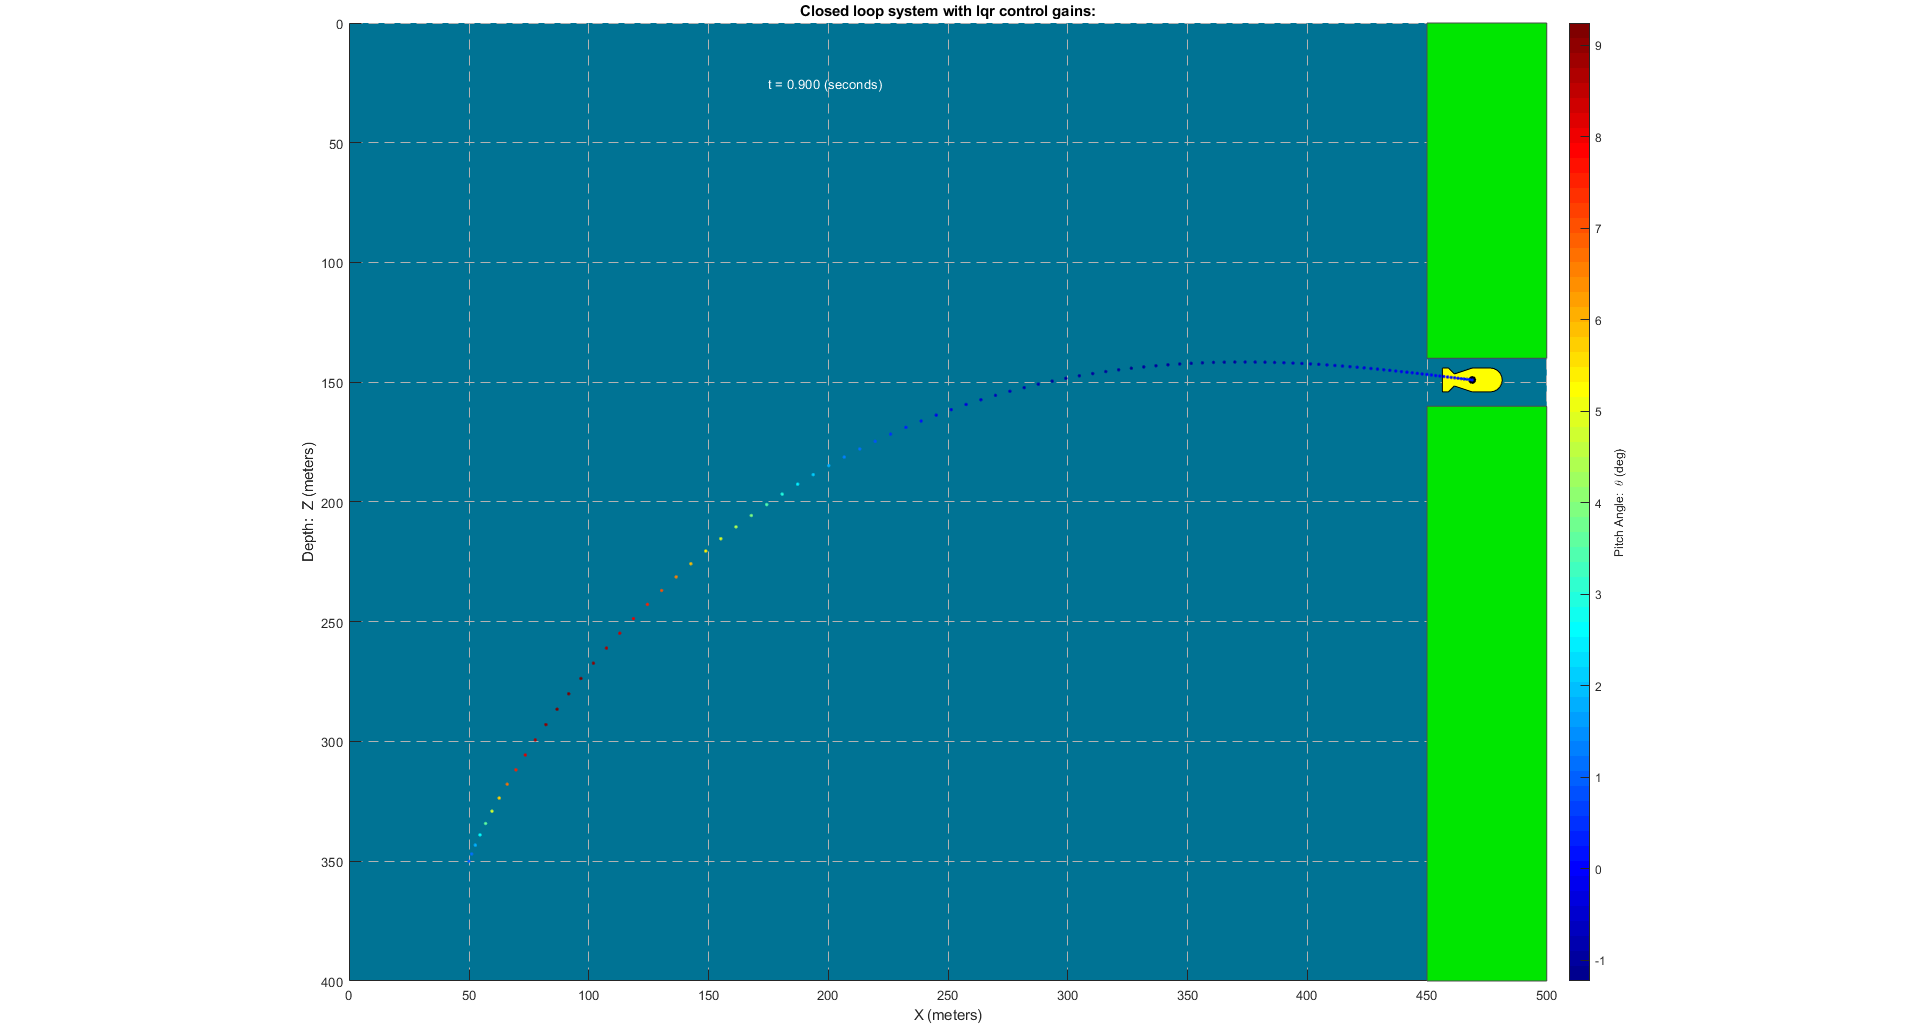


% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

% animate_auv(t,x,z,theta,savemovie);
animate_auv(t_lqr,Y_lqr(:,1),Y_lqr(:,2),Y_lqr(:,3), 0);
title('Closed loop system with lqr control gains:');
% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

# Observability

The** reason** we need to check for observability is because just like controller design problem we check for controllability, we need to check if the observability matrix is full rank such that we can arbitarily place poles of an observer we design.

If the rank of the observability matrix is equal to the maximum possible rank, then the system is **observable**.

**For example**: If we have aobservability matrix O, that has a rank N, where N is the number of columns of A matrix of size NxN, and matrix O is defined as $O=\left\lbrack C^{\prime } ,{A^{\prime } C}^{\prime } ,{A^{\prime } }^2 C^{\prime } ,{A^{\prime } }^3 C^{\prime } ,\ldotp \ldotp \ldotp \ldotp {A^{\prime } }^{N-1} C^{\prime } \right\rbrack$

In our Case, N = 6, and thus O martrix is full rank iff rank(O) = 6

**Note**: We also need to check which components of the Output Matrix feeding into the observable system after being multiplied by Matrix C have an impact on the observatibility of the system.

**Conclusion**: Since none of the subsets or combination of subsets of the outputs result in full rank observable matrix therefore there is no subset which is able to result in a fully observable system.

% Problem 2.

O_Observability = obsv(A_ol,C_ol); % Observability matrix with no outputs zero'd
Rank_O_Observability = rank(O_Observability);

disp(' The rank of the observability matrix is: ');

 The rank of the observability matrix is: 


disp(Rank_O_Observability);

     6



if Rank_O_Observability == 6
    disp(' Thus, the LTI system is completely observable ');
end

 Thus, the LTI system is completely observable 



% Trying to check if any subsets or combination of subsets of outputs can
% result in full observability

% for when y1 is zero'ed
C_without_Output_1 = C_ol;
C_without_Output_1(1,:) = [0;0;0;0;0;0]; % locking primary output y1 at zero
O_Observability_without_Output_1 = obsv(A_ol, C_without_Output_1);
Rank_O_Observability_without_Output_1 = rank(O_Observability_without_Output_1);
disp(' The rank of the observability matrix with Output 1 zerod is: ');

 The rank of the observability matrix with Output 1 zerod is: 


disp(Rank_O_Observability_without_Output_1);

     4




% for when y2 is locked at zero
C_without_Output_2 = C_ol;
C_without_Output_2(2,:) = [0;0;0;0;0;0]; % locking primary output y2 at zero
O_Observability_without_Output_2 = obsv(A_ol, C_without_Output_2);
Rank_O_Observability_without_Output_2 = rank(O_Observability_without_Output_2);
disp(' The rank of the observability matrix with Output 2 zerod is: ');

 The rank of the observability matrix with Output 2 zerod is: 


disp(Rank_O_Observability_without_Output_2);

     5




% for when y3 is locked at zero
C_without_Output_3 = C_ol;
C_without_Output_3(3,:) = [0;0;0;0;0;0]; % locking primary output y3 at zero
O_Observability_without_Output_3 = obsv(A_ol, C_without_Output_3);
Rank_O_Observability_without_Output_3 = rank(O_Observability_without_Output_3);
disp(' The rank of the observability matrix with Output 3 zerod is: ');

 The rank of the observability matrix with Output 3 zerod is: 


disp(Rank_O_Observability_without_Output_3);

     5




% for when y1 and y2 are locked at zero
C_without_Output_1_2 = C_ol;
C_without_Output_1_2(1,:) = [0;0;0;0;0;0]; % locking primary output y1 at zero
C_without_Output_1_2(2,:) = [0;0;0;0;0;0]; % locking primary output y2 at zero
O_Observability_without_Output_1_2 = obsv(A_ol, C_without_Output_1_2);
Rank_O_Observability_without_Output_1_2 = rank(O_Observability_without_Output_1_2);
disp(' The rank of the observability matrix with Output 1 & 2 zerod is: ');

 The rank of the observability matrix with Output 1 & 2 zerod is: 


disp(Rank_O_Observability_without_Output_1_2);

     3




% for when y1 and y3 are locked at zero
C_without_Output_1_3 = C_ol;
C_without_Output_1_3(1,:) = [0;0;0;0;0;0]; % locking primary output y1 at zero
C_without_Output_1_3(3,:) = [0;0;0;0;0;0]; % locking primary output y3 at zero
O_Observability_without_Output_1_3 = obsv(A_ol, C_without_Output_1_3);
Rank_O_Observability_without_Output_1_3 = rank(O_Observability_without_Output_1_3);
disp(' The rank of the observability matrix with Output 1 & 3 zerod is: ');

 The rank of the observability matrix with Output 1 & 3 zerod is: 


disp(Rank_O_Observability_without_Output_1_3);

     3




% for when y2 and y3 are locked at zero
C_without_Output_2_3 = C_ol;
C_without_Output_2_3(2,:) = [0;0;0;0;0;0]; % locking primary output y1 at zero
C_without_Output_2_3(3,:) = [0;0;0;0;0;0]; % locking primary output y2 at zero
O_Observability_without_Output_2_3 = obsv(A_ol, C_without_Output_2_3);
Rank_O_Observability_without_Output_2_3 = rank(O_Observability_without_Output_2_3);
disp(' The rank of the observability matrix with Output 2 & 3 zerod is: ');

 The rank of the observability matrix with Output 2 & 3 zerod is: 


disp(Rank_O_Observability_without_Output_2_3);

     2



# Design Luenberger Observer

**Reason****: **In many systems of practical importance, the entire state vector is not available for measurement. Thus a dynamic state estimator (like Luenberger Observer) can be designed to construct an approximation to the full state vector on the basis of available measurements (using actual outputs y)

% Problem 3a.

% Build a Luenberger observer for the CLOSED LOOP dynamic system
% Estimations will thus assume the control thrust are set ON, etc.

% Luenberger observer matrices
A_obs_closed = A_closed; 
A_obs_open = A_ol; 
B_obs = B_ol;
C_obs = C_ol;
D_obs = D_ol;

% We need A_obs', C_obs' and the eigenvalues of the desired system first

% First display the current pole locations, and then ramp up the gains by a
% factor of 10 or so without worrying about control effort, because the 
% observer is purely virtual. Pole locations (eigenvalues) of lone system:

% Display Natural Frequency, Damping Ratio and Poles of the Open-loop
% system
disp(' Poles information for Open-loop System: ')

 Poles information for Open-loop System: 


damp(ol_sys)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00              Inf    
  0.00e+00    -1.00e+00       0.00e+00              Inf    
  0.00e+00    -1.00e+00       0.00e+00              Inf    
 -1.82e-01     1.00e+00       1.82e-01         5.49e+00    
 -2.24e-01     1.00e+00       2.24e-01         4.47e+00    
 -1.58e+00     1.00e+00       1.58e+00         6.31e-01    



% Display Natural Frequency, Damping Ratio and Poles of the Closed-loop
% system using LQR optimal control gains
disp(' Poles information for Closed-loop System using LQR gains: ')

 Poles information for Closed-loop System using LQR gains: 


damp(cl_sys)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -2.70e+00 + 2.70e+00i     7.08e-01       3.82e+00         3.70e-01    
 -2.70e+00 - 2.70e+00i     7.08e-01       3.82e+00         3.70e-01    
 -5.41e+00 + 5.33e+00i     7.12e-01       7.59e+00         1.85e-01    
 -5.41e+00 - 5.33e+00i     7.12e-01       7.59e+00         1.85e-01    
 -1.55e+01 + 1.55e+01i     7.07e-01       2.19e+01         6.46e-02    
 -1.55e+01 - 1.55e+01i     7.07e-01       2.19e+01         6.46e-02    


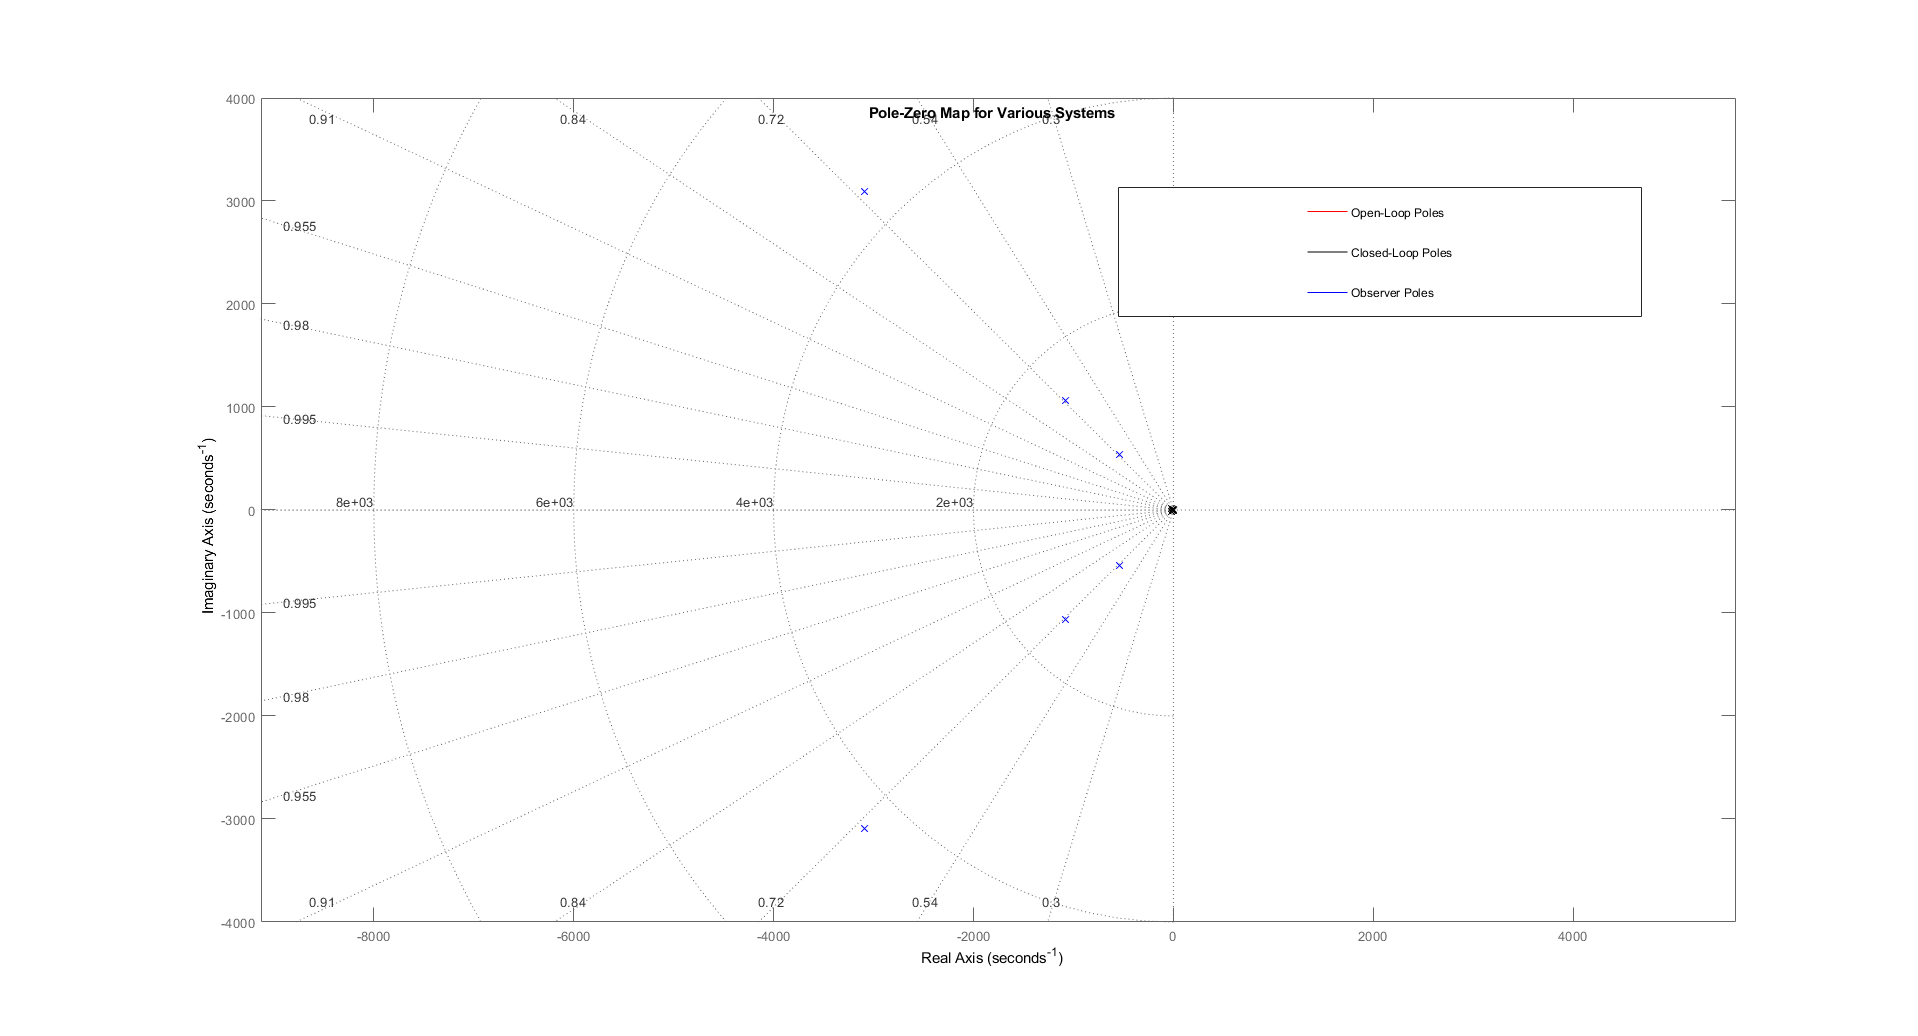


% Extracting Poles for both Open-loop and Closed Loop System
[Wn_ol, Z_ol, OL_Poles] = damp(ol_sys);
[Wn_cl, Z_cl, CL_Poles] = damp(cl_sys);

% Push them reasonalby far left, as control effort is not an issue for 
% this purely virtual system
%Note: Increasing Damping (wn) speeds up the convergence of the observer
%response and the plant (Actual response)
Desired_Obs_Poles = 200*CL_Poles; % make w_n 200 times larger for desired

% To Build the  observer:
% We first find its gain matrix K, and then create a state space model using (A-KC,B,C,D) 
K_obs = place(A_obs_closed', C_obs', Desired_Obs_Poles)';
A_KC = ss(A_obs_closed - K_obs*C_obs, B_obs, C_obs, D_obs); 

% Separating the imaginary and real parts of all poles in order to plot
% First, Luenberger Observer Poles
Desired_Obs_Poles_Real = real(Desired_Obs_Poles); % Real parts
Desired_Obs_Poles_Imag = imag(Desired_Obs_Poles); % Imaginary parts

% Second Closed-loop poles
CL_poles_real = real(CL_Poles);
CL_poles_imag = imag(CL_Poles);

% Third, Open-loop poles
OL_poles_real = real(OL_Poles);
OL_poles_imag = imag(OL_Poles);

% Actually plot all the poles
figure()

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

pzmap(ol_sys, 'r') % plot the open-loop poles/zeros on a p-z chart
%scatter(OL_poles_real,OL_poles_imag, 'r x')

hold on
pzmap(cl_sys, 'k') % plot the closed-loop poles/zeros on the p-z chart
%scatter(CL_poles_real,CL_poles_imag, 'k x')

% now plot the desired observer poles on the p-z chart
pzmap(A_KC, 'b') % observer poles from sys: [A_obs-K_obs*C, B_obs, C_obs, D_obs]
% scatter(Desired_Obs_Poles_Real,Desired_Obs_Poles_Imag, 'b x')

sgrid
axis equal

% xlim([-250, 0]);
legend4 = legend('Open-Loop Poles', 'Closed-Loop Poles', 'Observer Poles');
set(legend4,'Position',... 
    [0.5827381,0.693650797056,0.27321428,0.12619047274]);
title('Pole-Zero Map for Various Systems');
hold off

# Simulate Luenberger Observer

For a dynamic state estimator (observer)

**Note**: The Augmented state-space system has twice as many states and outputs as the plant.

For the open-loop response:

$\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{\widehat{x} } 
\end{array}\right\rbrack$ = $\left\lbrack \begin{array}{cc}
A & 0\\
\mathrm{KC} & \hat{A} -K\hat{C} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
B\\
\hat{B} +K\left(D-\hat{D} \right)
\end{array}\right\rbrack u$

can also be written as $\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{\widehat{x} } 
\end{array}\right\rbrack$ = $\overline{A}$$\left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack$ + $\bar{B} u$

$\left\lbrack \begin{array}{c}
y\\
\hat{y} 
\end{array}\right\rbrack \;$ =  $\left\lbrack \begin{array}{cc}
C & 0\\
0 & \hat{C} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
D\\
\hat{D} 
\end{array}\right\rbrack u$

can also be written as $\left\lbrack \begin{array}{c}
y\\
\hat{y} 
\end{array}\right\rbrack$ = $\bar{C}$$\left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack$ + $\bar{D} u$

Here $\hat{x}$ and $\hat{y}$ are the dynamic estimator x and y's, such that the state estimation error dynamics is e = x - $\hat{x}$

For the closed-loop response:

$\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{\widehat{x} } 
\end{array}\right\rbrack$ = $\left\lbrack \begin{array}{cc}
A & -\mathrm{BG}\\
\mathrm{KC} & \left(A-\mathrm{KC}-\mathrm{BG}\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack$

can also be written as $\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{\widehat{x} } 
\end{array}\right\rbrack$ = $\overline{A}$$\left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack$ + $\bar{B} u$

$\left\lbrack \begin{array}{c}
y\\
\hat{y} 
\end{array}\right\rbrack \;$ =  $\left\lbrack \begin{array}{cc}
C & -\mathrm{DG}\\
0 & \left(C-\mathrm{DG}\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack$

can also be written as $\left\lbrack \begin{array}{c}
y\\
\hat{y} 
\end{array}\right\rbrack$ = $\bar{C}$$\left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack$ + $\bar{D} u$

**Note**: In order to Simulate, Our 1st stage is an LTI model i.e. an augmented system including open-loop plant and observer without state feedback control

2nd Stage is the same augmented system, but now includes the state feedback control i.e we switch on the controller once the stage 2 begins

## **Performance requirements:**

- $\left|X_T \right|\le U_{\mathrm{max}\;}$          where   $U_{\mathrm{max}\;}$ = 3000000 N or 3e6 N

- 
$$\left|Z_s \right|\le U_{\mathrm{max}\;}$$


- 
$$\left|Z_b \right|\le U_{\mathrm{max}\;}$$


- AUV must completely enter the tunnel without contacting the barrier

- Simulation time for Stage 1 alone should be between 0.1s to 0.5s

- Total Simulation time including both stage 1 and stage 2 should be between 1.2s to 2s

- 5% Settling time of all three outputs must be less than 1 second.

## **Requirements Passed:**

- 5% Settling times: X - 0.927 seconds, Z - 0.45 seconds , $\theta$ - 0.81 seconds

- Input Control Signal:  $X_T$ - 6e+5, $Z_s$ - 2e+6, $Z_b$ - 2.95e+6

- Stage 1 Simulation Time: 0.1 seconds

- All the estimated outputs converge to actual outputs

- Time of Convergence:  X - 0.057 seconds, Z - 0.061 seconds , $\theta$ - 0.062 seconds

- Time Taken for AUV to Enter the Tunnel/Total Simulation Time: 1.3 seconds

% Problem 3b.

% Note that I actually use different augmented matrixes here for SUPERIOR 
% estimation performance: one for pure open loop, and one for when the 
% control signal is engaged. I understand this is not REQURIED, but in our 
% case, the observer is greatly benefitted by knowledge on whether the 
% control signal is engaged or not. We realize this concept via changing 
% "A_bar", which this observer utilizes to better estimate our changed 
% system parameters. 

% Construct augmented matrices for the open and closed-loop systems:

A_bar_ol = [A_ol,           zeros(6,6);....                     % L13/S26
            K_obs*C_ol,     (A_obs_open - K_obs*C_obs)];
A_bar_cl = [A_ol,            -B_ol*K_lqr;...                    % L14/S3
            K_obs*C_ol,     (A_ol - K_obs*C_ol - B_ol*K_lqr)];

B_bar_ol = [B_ol; (B_obs + K_obs*(D_ol - D_obs))];                % L13/S26

C_bar_ol = [C_ol, zeros(3,6);...                                % L13/S26
            zeros(3,6), C_obs];               
C_bar_cl = [C_ol, -D_ol*K_lqr;...
            zeros(3,6), (C_ol - D_ol*K_lqr)];                   % L14/S3

D_bar_ol = [D_ol; D_obs];                                       % L13/S26

% Constructing Both Stages of LTI State Space systems
Stage_one_sys = ss(A_bar_ol, B_bar_ol, C_bar_ol, D_bar_ol);
Stage_two_sys = ss(A_bar_cl, [], C_bar_cl, []);

% Setting initial OBSERVER values to 0
State_Variable_Vector_obs_0 = [State_Variable_Vector_0; 0; 0; 0; 0; 0; 0]; 

% Simulating stage one for 0.5 sec
tfinal_stage_one = 0.1;
[Y_Stage_one,t_Stage_one,X_Stage_one] = initial(Stage_one_sys, State_Variable_Vector_obs_0, tfinal_stage_one); 

% We need to cut those x and z values back for final plot
Y_Stage_one(:,1) = Y_Stage_one(:,1) + 463;
Y_Stage_one(:,2) = Y_Stage_one(:,2) + 150;

% Note we also need to apply translation to observer states
Y_Stage_one(:,4) = Y_Stage_one(:,4) + 463;
Y_Stage_one(:,5) = Y_Stage_one(:,5) + 150;

% Converting the theta angle from degrees to radians
Y_Stage_one(:,3) = (Y_Stage_one(:,3)*pi/180);
X_Stage_one(:,6) = (X_Stage_one(:,6)*pi/180);

Y_Stage_one(:,6) = (Y_Stage_one(:,6)*pi/180);
X_Stage_one(:,12) = (X_Stage_one(:,12)*pi/180);

%%%%%%%%%%%%%%%%%%%% Simulating Stage 1 %%%%%%%%%%%%%%%%%%%%
% Calculating 5% Settling time for all three outputs of Stage two system
SimulationStuff1_Stage_one = lsiminfo(Y_Stage_one(:,1),t_Stage_one,'SettlingTimeThreshold',0.05);
SimulationStuff2_Stage_one = lsiminfo(Y_Stage_one(:,2),t_Stage_one,'SettlingTimeThreshold',0.05);
SimulationStuff3_Stage_one = lsiminfo(Y_Stage_one(:,3),t_Stage_one,'SettlingTimeThreshold',0.05);

% Position in X (x) at 5% Settling time, 
X_at_SettlingTime_Stage_one = interp1(t_Stage_one(:,1),Y_Stage_one(:,1),SimulationStuff1_Stage_one.SettlingTime);


% Depth(z) at 5% Settling time, 
Depth_at_SettlingTime_Stage_one = interp1(t_Stage_one(:,1),Y_Stage_one(:,2),SimulationStuff2_Stage_one.SettlingTime);

% Pitch Angle (theta) at 5% Settling time, 
PitchAngle_at_SettlingTime_Stage_one = interp1(t_Stage_one(:,1),Y_Stage_one(:,3),SimulationStuff3_Stage_one.SettlingTime);

% show the settling time for each output: 
T_Stage_one = table({'x in meter'; 'z in meter'; 'theta in rad'}, [X_at_SettlingTime_Stage_one ;Depth_at_SettlingTime_Stage_one; PitchAngle_at_SettlingTime_Stage_one], [SimulationStuff1_Stage_one.SettlingTime; SimulationStuff2_Stage_one.SettlingTime; SimulationStuff3_Stage_one.SettlingTime]);
T_Stage_one.Properties.VariableNames = {'Output_Name','Output_Value','Settling_Time_in_s'};
disp('Table with outputs, output values and 5% Settling times for Stage One:');

Table with outputs, output values and 5% Settling times for Stage One:


disp(T_Stage_one);

     Output_Name      Output_Value    Settling_Time_in_s
    ______________    ____________    __________________

    'x in meter'          59.414           0.094957     
    'z in meter'          322.65           0.094802     
    'theta in rad'      0.020104           0.097393     



%%%%%%%%%%%%%%%%%%%% Simulating Stage 2 %%%%%%%%%%%%%%%%%%%%

% Get the observer's final state estimations for transition to second stage
% these will be the "initial conditions" of the states at the beginning of 
% the second stage:
State_Variable_Vector_obs_0_Stage_two = X_Stage_one(length(X_Stage_one(:,1)),:); 
[Y_Stage_two,t_Stage_two,X_Stage_two] = initial(Stage_two_sys, State_Variable_Vector_obs_0_Stage_two, 1.2); %simulate stage2 for 1.5s

% We need to cut those x and z values back for final plot
Y_Stage_two(:,1) = Y_Stage_two(:,1) + 463;
Y_Stage_two(:,2) = Y_Stage_two(:,2) + 150;

% Note we also need to apply translation to observer states
Y_Stage_two(:,4) = Y_Stage_two(:,4) + 463;
Y_Stage_two(:,5) = Y_Stage_two(:,5) + 150;

% Converting the theta angle from degrees to radians
Y_Stage_two(:,3) = (Y_Stage_two(:,3)*pi/180);
X_Stage_two(:,6) = (X_Stage_two(:,6)*pi/180);

Y_Stage_two(:,6) = (Y_Stage_two(:,6)*pi/180);
X_Stage_two(:,12) = (X_Stage_two(:,12)*pi/180);

% Calculating 5% Settling time for all three outputs of Stage two system
SimulationStuff1_Stage_two = lsiminfo(Y_Stage_two(:,1),t_Stage_two,'SettlingTimeThreshold',0.05);
SimulationStuff2_Stage_two = lsiminfo(Y_Stage_two(:,2),t_Stage_two,'SettlingTimeThreshold',0.05);
SimulationStuff3_Stage_two = lsiminfo(Y_Stage_two(:,3),t_Stage_two,'SettlingTimeThreshold',0.05);

% Position in X (x) at 5% Settling time, 
X_at_SettlingTime_Stage_two = interp1(t_Stage_two(:,1),Y_Stage_two(:,1),SimulationStuff1_Stage_two.SettlingTime);


% Depth(z) at 5% Settling time, 
Depth_at_SettlingTime_Stage_two = interp1(t_Stage_two(:,1),Y_Stage_two(:,2),SimulationStuff2_Stage_two.SettlingTime);

% Pitch Angle (theta) at 5% Settling time, 
PitchAngle_at_SettlingTime_Stage_two = interp1(t_Stage_two(:,1),Y_Stage_two(:,3),SimulationStuff3_Stage_two.SettlingTime);

% show the settling time for each output: 
T_Stage_two = table({'x in meter'; 'z in meter'; 'theta in rad'}, [X_at_SettlingTime_Stage_two ;Depth_at_SettlingTime_Stage_two; PitchAngle_at_SettlingTime_Stage_two], [SimulationStuff1_Stage_two.SettlingTime; SimulationStuff2_Stage_two.SettlingTime; SimulationStuff3_Stage_two.SettlingTime]);
T_Stage_two.Properties.VariableNames = {'Output_Name','Output_Value','Settling_Time_in_s'};
disp('Table with outputs, output values and 5% Settling times for Stage Two:');

Table with outputs, output values and 5% Settling times for Stage Two:


disp(T_Stage_two);

     Output_Name      Output_Value    Settling_Time_in_s
    ______________    ____________    __________________

    'x in meter'           459.05          0.82994      
    'z in meter'           158.82          0.35318      
    'theta in rad'     -0.0062541          0.71227      




t_Stage_two = t_Stage_two + tfinal_stage_one; % now alter the second simulation time so it is continuous

% Appending Solutions from both stages for plotting
Y_net = [Y_Stage_one;Y_Stage_two];
X_net = [X_Stage_one;X_Stage_two];
CtrlThrust_net = [zeros(length(t_Stage_one),3); [K_lqr*X_Stage_two(:,7:12)']']; % G * (estimated X)'
t_net = [t_Stage_one;t_Stage_two];

Max_of_Thrust_X_T_net = max(CtrlThrust_net(:,1));
Max_of_Stern_Thrust_Z_s_net = max(CtrlThrust_net(:,2));
Max_of_Bow_Thrust_Z_b_net = max(CtrlThrust_net(:,3));

fprintf(' Max Thrust X_T at Net Stage is: %6.f N or %.1e N ', Max_of_Thrust_X_T_net, Max_of_Thrust_X_T_net);

 Max Thrust X_T at Net Stage is: 589892 N or 5.9e+05 N 

fprintf(' Max Stern Thrust Z_s at Net Stage is: %6.f N or %.1e N ', Max_of_Stern_Thrust_Z_s_net, Max_of_Stern_Thrust_Z_s_net);

 Max Stern Thrust Z_s at Net Stage is: 1695486 N or 1.7e+06 N 

fprintf(' Max Bow Thrust Z_b at Net Stage is: %6.f N or %.1e N ', Max_of_Bow_Thrust_Z_b_net, Max_of_Bow_Thrust_Z_b_net);

 Max Bow Thrust Z_b at Net Stage is: 2445613 N or 2.4e+06 N 

% Calculating 5% Settling time for all three outputs of Stage two system
SimulationStuff1_net = lsiminfo(Y_net(:,1),t_net,'SettlingTimeThreshold',0.05);
SimulationStuff2_net = lsiminfo(Y_net(:,2),t_net,'SettlingTimeThreshold',0.05);
SimulationStuff3_net = lsiminfo(Y_net(:,3),t_net,'SettlingTimeThreshold',0.05);

% To check when my estimated output converges to actual output data
Converging_x_index = 0;
Converging_z_index = 0;
Converging_theta_index = 0;

for index1 = 1:length(t_net)
    if Y_net(index1,1) == Y_net(index1,4)
        Converging_x_index = index1;
    end
    if Converging_x_index ~= 0
        % disp('Index position of output x when it is 1st equal in both estimated and actual output x vectors is:')
        % disp(Converging_x_index);
        disp(' Time in sec at which estimated output x converges to actual output x is: ')
        disp(t_net(Converging_x_index));
        break
    end
end

 Time in sec at which estimated output x converges to actual output x is: 


    0.0570




for index2 = 1:length(t_net)
    if Y_net(index2,2) == Y_net(index2,5)
        Converging_z_index = index2;
    end
    if Converging_z_index ~= 0
        % disp('Index position of output z when it is 1st equal in both estimated and actual output z vectors is:')
        % disp(Converging_z_index);
        disp('Time in sec at which estimated output z converges to actual output z is:')
        disp(t_net(Converging_z_index));
        break
    end
end

Time in sec at which estimated output z converges to actual output z is:


    0.0606




for index3 = 1:length(t_net)
    if Y_net(index3,3) == Y_net(index3,6)
        Converging_theta_index = index3;
    end
    if Converging_theta_index ~= 0
        % disp('Index position of output theta when it is 1st equal in both estimated and actual output theta vectors is:')
        % disp(Converging_theta_index);
        disp('Time in sec at which estimated output theta converges to actual output theta is:')
        disp(t_net(Converging_theta_index));
        break
    end
end

Time in sec at which estimated output theta converges to actual output theta is:


    0.0620



% Since I am getting some repeated values for Y_net(:,1) and Y_net(:,2), therefore I
% cannot perform interpolation until I make my Y_net vector unique i.e
% remove the repeated elements

[Y_net_unique1(:,1), index_net_1] = unique(Y_net(:,1));
[Y_net_unique2(:,1), index_net_2] = unique(Y_net(:,2));

% Position in X (x) at 5% Settling time, 
X_at_SettlingTime_net = interp1(t_net(index_net_1,1),Y_net_unique1(:,1),SimulationStuff1_net.SettlingTime);
% Depth(z) at 5% Settling time, 
Depth_at_SettlingTime_net = interp1(t_net(index_net_2,1),Y_net_unique2(:,1),SimulationStuff2_net.SettlingTime);
% Pitch Angle (theta) at 5% Settling time, 
PitchAngle_at_SettlingTime_net = Y_net(3420,3);

% show the settling time for each output: 
T_net = table({'x in meter'; 'z in meter'; 'theta in rad'}, [X_at_SettlingTime_net ;Depth_at_SettlingTime_net; PitchAngle_at_SettlingTime_net], [SimulationStuff1_net.SettlingTime; SimulationStuff2_net.SettlingTime; SimulationStuff3_net.SettlingTime]);
T_net.Properties.VariableNames = {'Output_Name','Output_Value','Settling_Time_in_s'};
disp(' Table with Actual outputs, output values and 5% Settling times at Net of two Stages: ');

 Table with Actual outputs, output values and 5% Settling times at Net of two Stages: 


disp(T_net);

     Output_Name      Output_Value    Settling_Time_in_s
    ______________    ____________    __________________

    'x in meter'           458.55          0.92696      
    'z in meter'           160.26          0.44625      
    'theta in rad'     -0.0064718          0.81227      




% Calculating 5% Settling time for all three estimated outputs of Stage two system
SimulationStuff1_net_estimated = lsiminfo(Y_net(:,4),t_net,'SettlingTimeThreshold',0.05);
SimulationStuff2_net_estimated = lsiminfo(Y_net(:,5),t_net,'SettlingTimeThreshold',0.05);
SimulationStuff3_net_estimated = lsiminfo(Y_net(:,6),t_net,'SettlingTimeThreshold',0.05);

% show the settling time for each output: 

T_net_estimated = table({'x in meter'; 'z in meter'; 'theta in rad'}, [SimulationStuff1_net_estimated.SettlingTime; SimulationStuff2_net_estimated.SettlingTime; SimulationStuff3_net_estimated.SettlingTime]);
T_net_estimated.Properties.VariableNames = {'Output_Name','Settling_Time_in_s'};
disp(' Table with Estimated outputs, and 5% Settling times at Net of two Stages: ');

 Table with Estimated outputs, and 5% Settling times at Net of two Stages: 


disp(T_net_estimated);

     Output_Name      Settling_Time_in_s
    ______________    __________________

    'x in meter'           0.90982      
    'z in meter'           0.43473      
    'theta in rad'         0.33707      



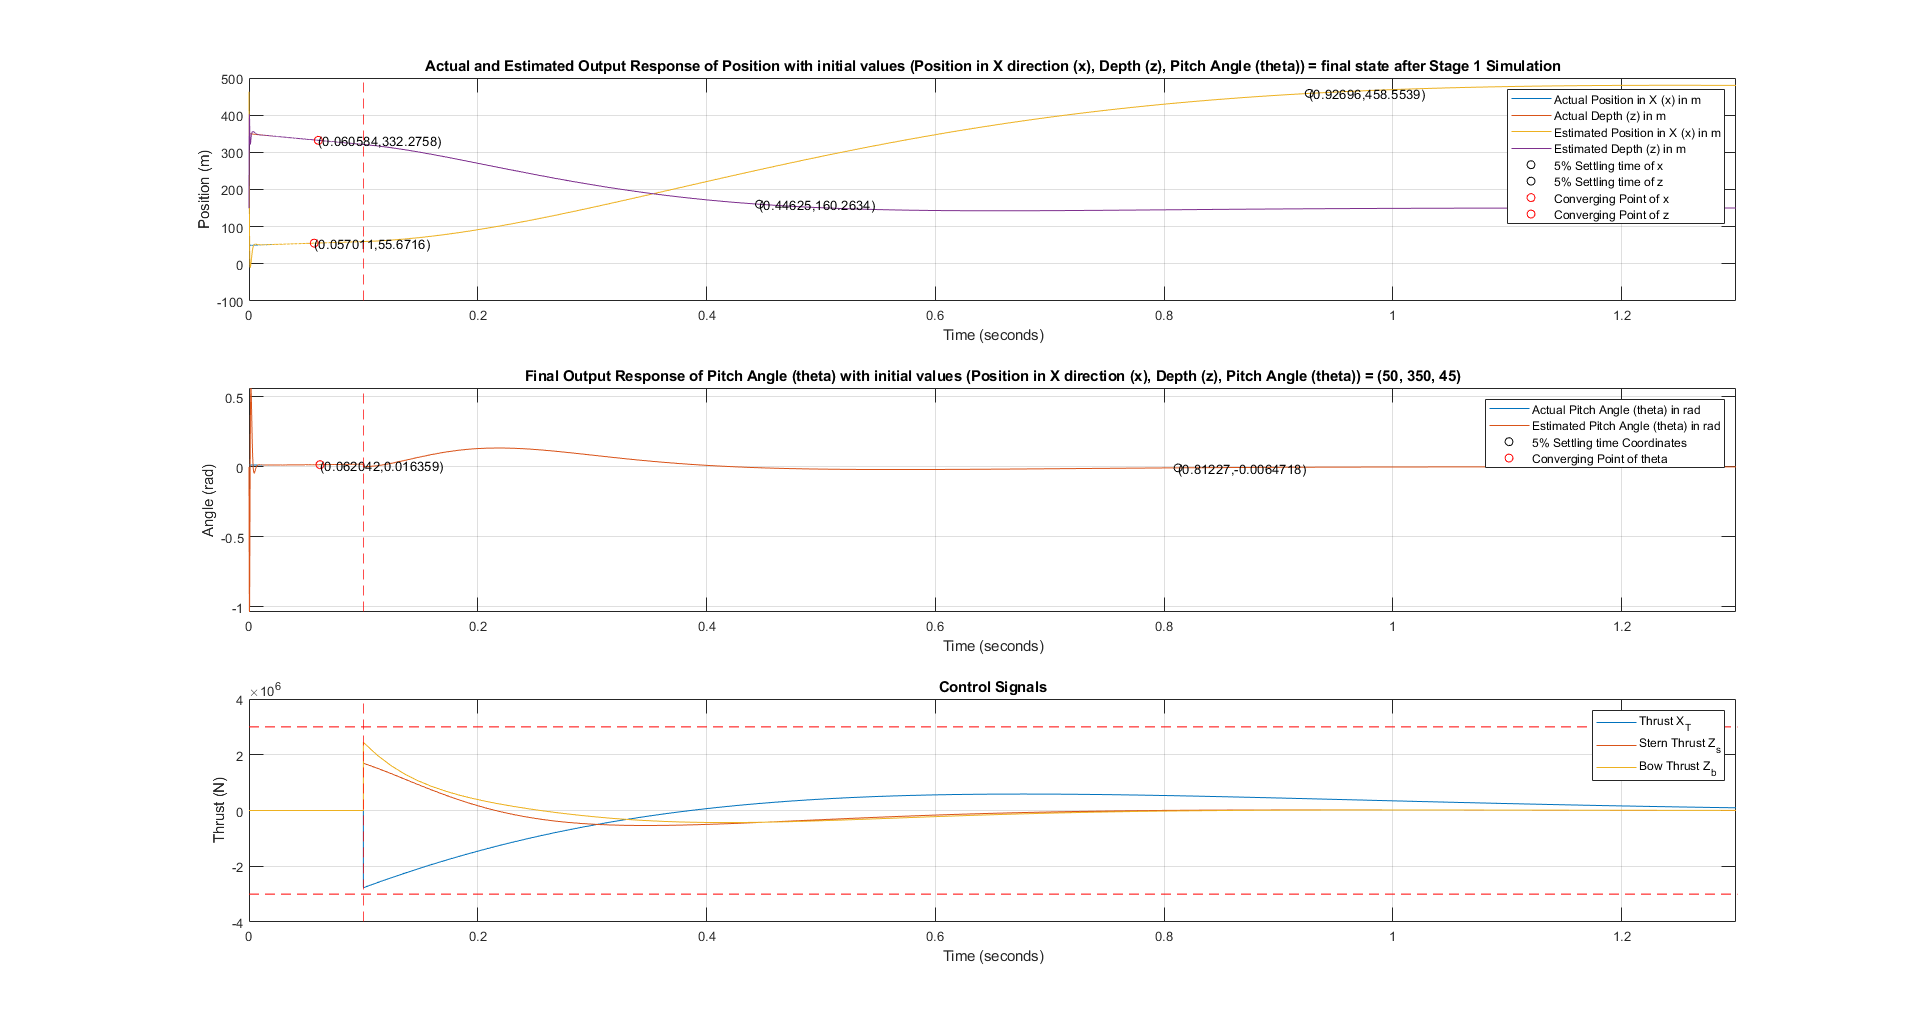


figure()
% Construct the 1st plot of just Positions in m
subplot(3,1,1)
plot(t_net,Y_net(:,1));
grid on
hold on
plot(t_net,Y_net(:,2));
plot(t_net,Y_net(:,4));
plot(t_net,Y_net(:,5));
title(['Actual and Estimated Output Response of Position with initial values (Position in X direction (x), Depth (z), Pitch Angle (theta))',...
    ' = final state after Stage 1 Simulation']);
xlabel('Time (seconds)');
ylabel('Position (m)');
xlim([0 t_net(length(t_net))]);

plot(SimulationStuff1_net.SettlingTime, X_at_SettlingTime_net,'kO');
text(SimulationStuff1_net.SettlingTime, X_at_SettlingTime_net,['(' num2str(SimulationStuff1_net.SettlingTime) ',' num2str(X_at_SettlingTime_net) ')']);

plot(SimulationStuff2_net.SettlingTime, Depth_at_SettlingTime_net,'kO');
text(SimulationStuff2_net.SettlingTime, Depth_at_SettlingTime_net,['(' num2str(SimulationStuff2_net.SettlingTime) ',' num2str(Depth_at_SettlingTime_net) ')']);

plot(t_net(Converging_x_index), Y_net(Converging_x_index,1),'rO');
text(t_net(Converging_x_index), Y_net(Converging_x_index,1),['(' num2str(t_net(Converging_x_index)) ',' num2str(Y_net(Converging_x_index,1)) ')']);

plot(t_net(Converging_z_index), Y_net(Converging_z_index,2),'rO');
text(t_net(Converging_z_index), Y_net(Converging_z_index,2),['(' num2str(t_net(Converging_z_index)) ',' num2str(Y_net(Converging_z_index,2)) ')']);

vRefl=xline(tfinal_stage_one); 
set(vRefl,'color','r','linestyle','--'); % Vertical Reference line where Stage 1 simulation ends

legend('Actual Position in X (x) in m', 'Actual Depth (z) in m',...
       'Estimated Position in X (x) in m', 'Estimated Depth (z) in m',...
       '5% Settling time of x', '5% Settling time of z',...
       'Converging Point of x', 'Converging Point of z');
hold off

% Construct the 2nd Plot of just Pitch Angle in rad
subplot(3,1,2)
plot(t_net,Y_net(:,3));
hold on
grid on
plot(t_net,Y_net(:,6));
title(['Final Output Response of Pitch Angle (theta) with initial values (Position in X direction (x), Depth (z), Pitch Angle (theta))',...
    ' = (50, 350, 45)']);
xlabel('Time (seconds)')
ylabel('Angle (rad)');

plot(SimulationStuff3_net.SettlingTime, PitchAngle_at_SettlingTime_net,'kO');
text(SimulationStuff3_net.SettlingTime, PitchAngle_at_SettlingTime_net,['(' num2str(SimulationStuff3_net.SettlingTime) ',' num2str(PitchAngle_at_SettlingTime_net) ')']);

plot(t_net(Converging_theta_index), Y_net(Converging_theta_index,3),'rO');
text(t_net(Converging_theta_index), Y_net(Converging_theta_index,3),['(' num2str(t_net(Converging_theta_index)) ',' num2str(Y_net(Converging_theta_index,3)) ')']);

vRefl=xline(tfinal_stage_one); 
set(vRefl,'color','r','linestyle','--'); % Vertical Reference line where Stage 1 simulation ends

legend('Actual Pitch Angle (theta) in rad', 'Estimated Pitch Angle (theta) in rad',...
        '5% Settling time Coordinates', 'Converging Point of theta');
xlim([0 t_net(length(t_net))]);
% ylim([-0.3 1]);
hold off


% Plotting the Control Signals
subplot(3, 1, 3)
plot(t_net, CtrlThrust_net(:,1))
hold on
plot(t_net, CtrlThrust_net(:,2))
plot(t_net, CtrlThrust_net(:,3))
hRefl=refline(0,3e6);
set(hRefl,'color','r','linestyle','--'); % Max horizontal
hRef2=refline(0,-3e6);
set(hRef2,'color','r','linestyle','--'); % Min horizontal
hold off
grid on

vRefl=xline(tfinal_stage_one); 
set(vRefl,'color','r','linestyle','--'); % Vertical Reference line where Stage 1 simulation ends

legend('Thrust X_T', 'Stern Thrust Z_s', 'Bow Thrust Z_b');
xlabel('Time (seconds)');
ylabel('Thrust (N)');
title('Control Signals');
xlim([0 t_net(length(t_net))]);
ylim([-4e6 4e6]);
% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

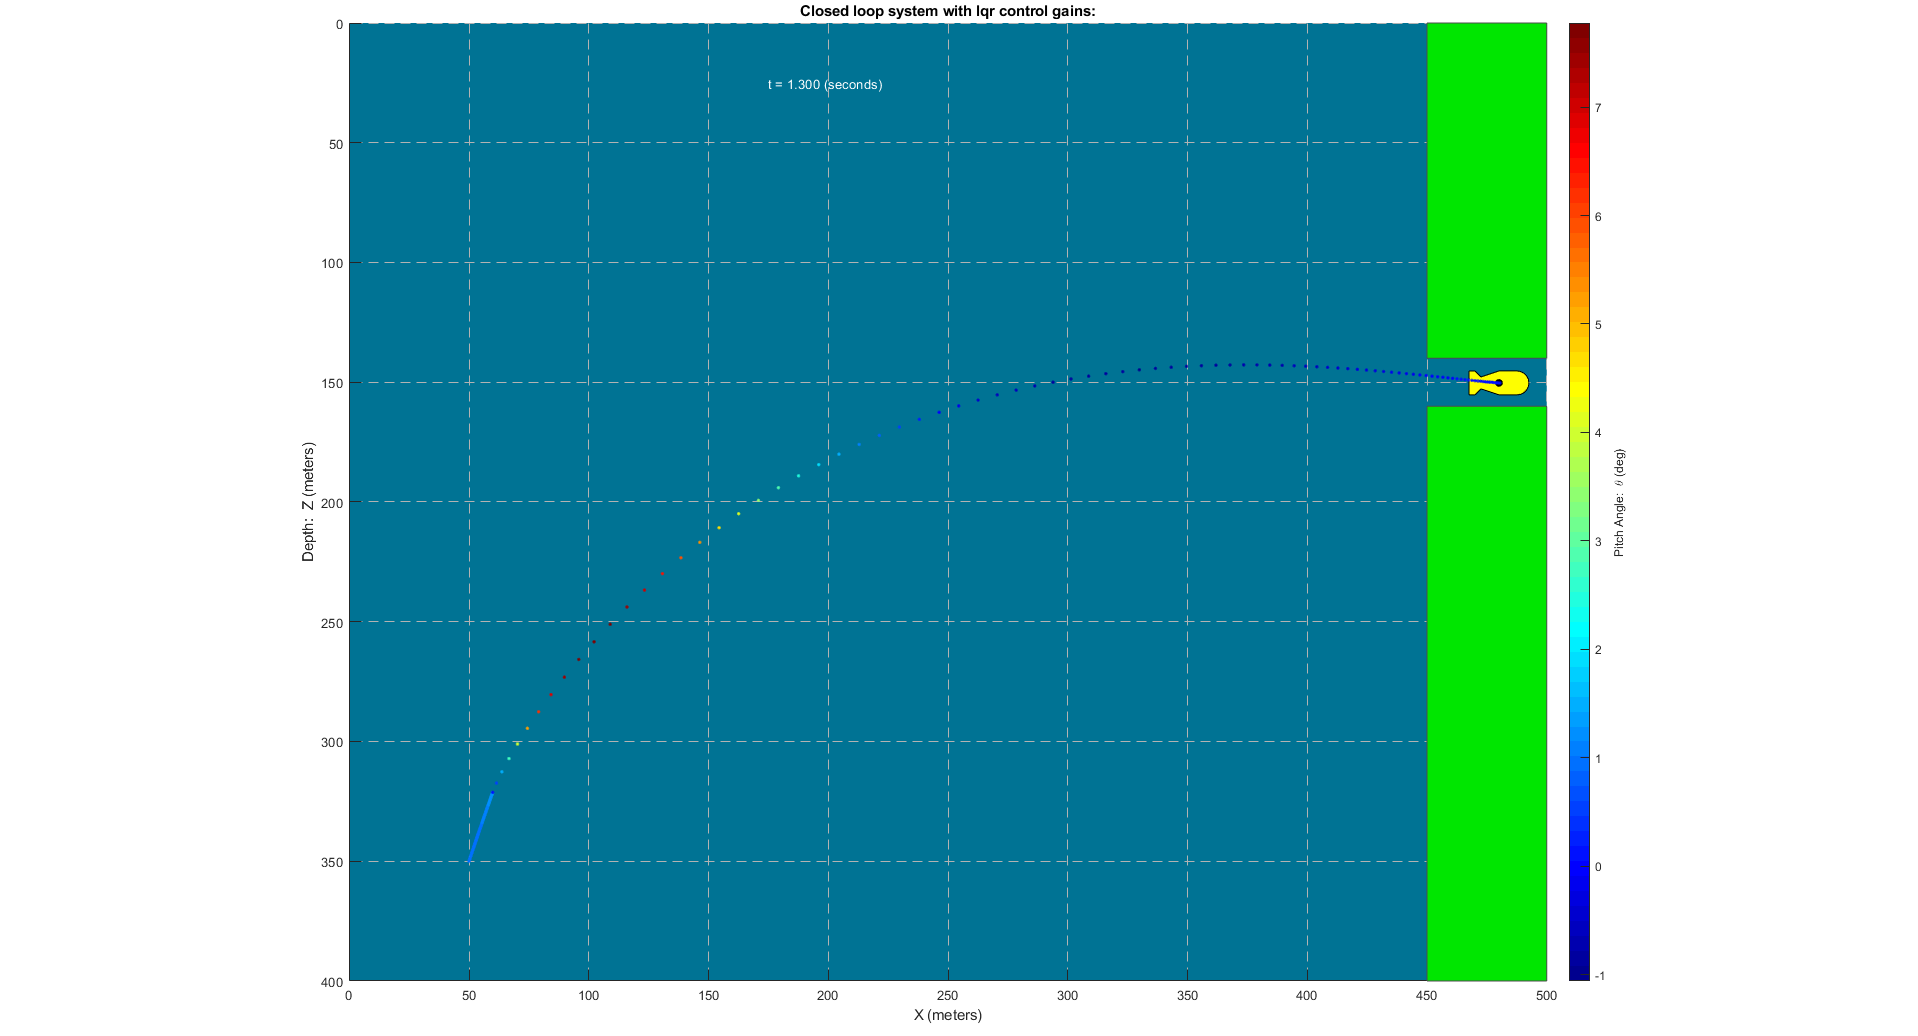

% animate_auv(t,x,z,theta,savemovie);
animate_auv(t_net,Y_net(:,1),Y_net(:,2),Y_net(:,3), 0);
title('Closed loop system with lqr control gains:');
% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

# Design State Feedback Gain Matrix with integral Control (LQI)


$${\dot{Q} }_{\mathrm{LQI}} ={\left\lbrack \begin{array}{cc}
Q_{6\mathrm{x6}}  & {\mathrm{zeros}}_{6\mathrm{x3}} \\
{\mathrm{zeros}}_{3\mathrm{x6}}  & {\mathrm{Diagonal}\;\mathrm{Integral}\;\mathrm{Gains}}_{3\mathrm{x3}} 
\end{array}\right\rbrack }_{9\mathrm{x9}}$$
  
$$\Rightarrow \;{\dot{Q} }_{\mathrm{LQI}} =\left\lbrack \begin{array}{ccccccccc}
Q & Q & Q & Q & Q & Q & 0 & 0 & 0\\
Q & Q & Q & Q & Q & Q & 0 & 0 & 0\\
Q & Q & Q & Q & Q & Q & 0 & 0 & 0\\
Q & Q & Q & Q & Q & Q & 0 & 0 & 0\\
Q & Q & Q & Q & Q & Q & 0 & 0 & 0\\
Q & Q & Q & Q & Q & Q & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & \mathrm{I1} & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & \mathrm{I2} & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \mathrm{I3}
\end{array}\right\rbrack$$


Once the LQI optimal state feedback gains is designed, we need to separate out the **State Feedback gains G0** and **Integral Feedback gains GI**

% % Problem 4a.

% Let's assume our Q_star (output weighing matrix) to be:
% Here Top left of the 9x9 matrix is the old Q (6x6) and bottom right is
% the Integrator Gains (3x3)
Q_star_lqi = [Q,          zeros(6,3);...
             zeros(3,6),  1e9*diag([3 500 755])];

Q_lqi = Q_star_lqi;
R_lqi = diag([1.5 0.1 0.05]); % Same as for LQR
% N = zeros(9, 3);
[K_lqi,S_lqi,P_lqi] = lqi(ol_sys, Q_lqi, R_lqi);
% where K_lqi contains both state feedback gain matrix and integral feedback gains, S is the Riccati solution and P
% are the closed loop eigen values

G0 = K_lqi(:,1:6); % first 6 columns, State Feedback gains
GI = K_lqi(:,7:9); % last 3 columns, Integral Feedback gains 

State_Feedback_Gains = G0;
Integral_Feedback_Gains = GI;

# Augmented Output Feedback Control System (LQI)

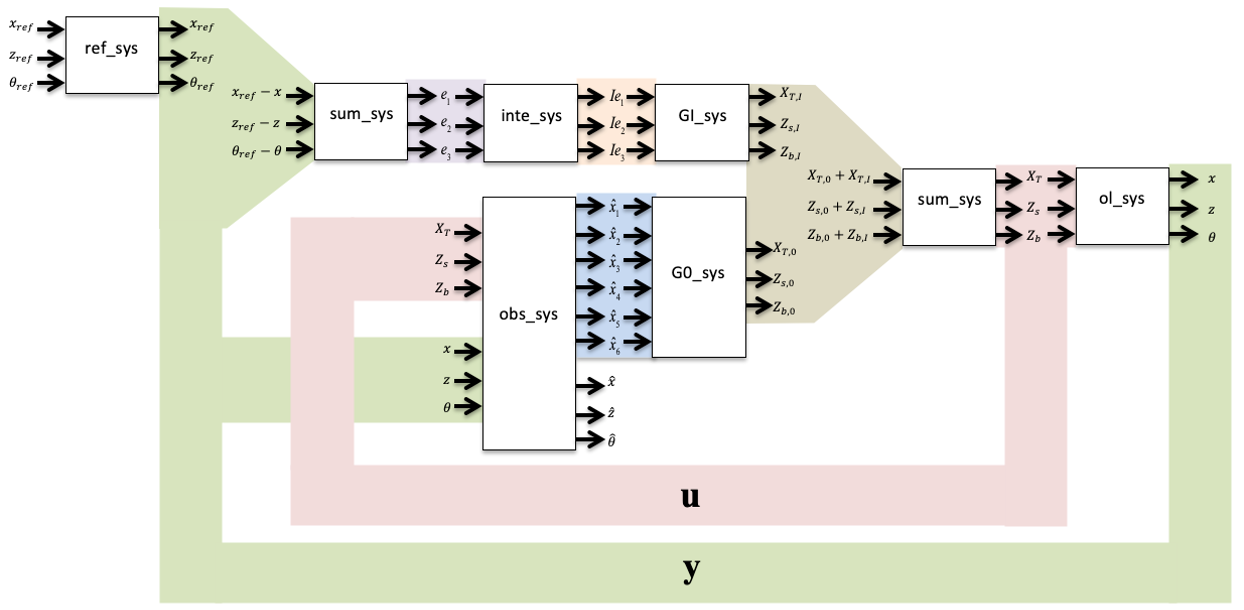

The block diagram above represents the complete **output feedback control system** including integration of reference tracking.

The **8 LTI objects** above need to be defined before using *APPEND *and *Connect *functions.

**Note:** 

- ol_sys is the LTI object from the Midterm_Project

- **obs_sys**: Inputs - u ($X_T \;,Z_S \;,Z_b$) and y (x, z, $\theta$), Output - Estimate state vector ($\hat{u} \;,\hat{w} \;,\hat{q} \;,\;\hat{x} ,\hat{z} ,\theta^ˆ$) and Estimated outputs ($\hat{x} ,\hat{z} ,\theta^ˆ$)

Use *APPEND *afunction to connect all the 8 LTI objects.

Use *CONNECT* to properly connect all the blocks together by defining which outputs of the appended system are connected to which inputs .

**Important**: Defining Inputs and Outputs of Each Subsystem LTI object

% % % Problem 4b.

% ===================== Constructing "obs_sys" ======================

A_star_obs = [A_obs_open - K_obs*C_obs + K_obs*D_obs*G0];
B_star_obs = [B_obs, K_obs];
C_star_obs = [eye(6); C_obs];
D_star_obs = [zeros(6,6); D_obs, zeros(3,3)];

obs_sys = ss(A_star_obs, B_star_obs, C_star_obs, D_star_obs);

% ============= Constructing remaining LTI objects ==============

ref_sys = tf(eye(3));                           % Static gain identity matrix
sum_sys = tf(eye(3));                           % Static gain identity matrix
G0_sys = tf(-G0);                              % Static proportional gain matrix (negated)
GI_sys = tf(-GI);                              % Static integral gain matrix (negated)
inte_sys = tf(num2cell(eye(3)),[1 0]);          % integrator matrix

% ====== Append all the lti objects to make on mega lti object ======

sys_append = append(ol_sys, obs_sys, ref_sys, sum_sys, inte_sys, G0_sys, GI_sys, sum_sys);


Q_connect = [1 2 3 4 5 6 7 8 9 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30;
    28 29 30 28 29 30 1 2 3 13 14 15 16 17 18 4 5 6 7 8 9 19 20 21 22 23 24;
    0 0 0 0 0 0 0 0 0 -1 -2 -3 0 0 0 0 0 0 0 0 0 0 0 0 25 26 27]';

In = [10 11 12];
Out = [1 2 3 10 11 12 28 29 30];

Final_LTI_sys = connect(sys_append, Q_connect, In, Out);


# Simulating closed loop response of LQI Output Feedback Controller with integral Control using LTI model constructed in Problem 4b

## **Performance requirements:**

- No requirement or limit on control signal but it should converge to 0 eventually.

- All estimated outputs should converge to corresponding actual outputs.

- All actual outputs should converge to the desired references with 0 steady state error and within the required time limit

- AUV must completely enter the tunnel without contacting the barrier

- 5% Settling time of all three outputs must be less than 1 second.

## **Requirements Passed:**

- 5% Settling times: X - 0.92 seconds, Z - 0.35 seconds , $\theta$ - 0.33 seconds

- All the estimated outputs converge to actual outputs

- All actual outputs converge to the desired references with 0 steady state error within 

- Time Taken for AUV to Enter the Tunnel/Total Simulation Time: 0.7 seconds

% Problem 4c.

% Initial Condition of State Vector(1x6) augmented with 0 vector for initial
% observer states(1x6) and augmented 0 vector (1x3) for initial integral states
State_Variable_Vector_0_lqi = [State_Variable_Vector_0; 0; 0; 0; 0; 0; 0; 0; 0; 0]; 

% Because I did translation for all previous problems but we do not need it
% for this
State_Variable_Vector_0_lqi(4,1) = State_Variable_Vector_0_lqi(4,1) + 463;
State_Variable_Vector_0_lqi(5,1) = State_Variable_Vector_0_lqi(5,1) + 150;

% Simulating stage one for 2 sec
tfinal_lqi = 1;
% Time Vector:
t_lqi = 0:0.001:tfinal_lqi;

% Creating Reference Input Vectors
refrence_input = zeros(length(t_lqi), 3); 
refrence_input(:,1) = 463;
refrence_input(:,2) = 150;
refrence_input(:,3) = 0;


% Simulating the Response
[Y_final_lqi, t_final_lqi, X_final_lqi] = lsim(Final_LTI_sys, refrence_input', t_lqi, State_Variable_Vector_0_lqi);

Y_final_actual = Y_final_lqi(:,1:3);
Y_final_estimated = Y_final_lqi(:,4:6);
CtrlThrust_final_lqi = Y_final_lqi(:,7:9);



% Calculating 5% Settling time for all three actual outputs of final LTI
% system
SimulationStuff1_final_lqi = lsiminfo(Y_final_actual(:,1),t_final_lqi,'SettlingTimeThreshold',0.05);
SimulationStuff2_final_lqi = lsiminfo(Y_final_actual(:,2),t_final_lqi,'SettlingTimeThreshold',0.05);
SimulationStuff3_final_lqi = lsiminfo(Y_final_actual(:,3),t_final_lqi,'SettlingTimeThreshold',0.05);

% Position in X (x) at 5% Settling time, 
X_at_SettlingTime_final_lqi = interp1(t_final_lqi(:,1),Y_final_actual(:,1),SimulationStuff1_final_lqi.SettlingTime);

% Depth(z) at 5% Settling time, 
Depth_at_SettlingTime_final_lqi = interp1(t_final_lqi(:,1),Y_final_actual(:,2),SimulationStuff2_final_lqi.SettlingTime);

% Pitch Angle (theta) at 5% Settling time, 
PitchAngle_at_SettlingTime_final_lqi = interp1(t_final_lqi(:,1),Y_final_actual(:,3),SimulationStuff3_final_lqi.SettlingTime);

% Show the settling time for each actual output: 
T_final_lqi = table({'x in meter'; 'z in meter'; 'theta in rad'}, [X_at_SettlingTime_final_lqi ;Depth_at_SettlingTime_final_lqi; PitchAngle_at_SettlingTime_final_lqi], [SimulationStuff1_final_lqi.SettlingTime; SimulationStuff2_final_lqi.SettlingTime; SimulationStuff3_final_lqi.SettlingTime]);
T_final_lqi.Properties.VariableNames = {'Output_Name','Output_Value','Settling_Time_in_s'};
disp('Table with actual outputs, output values and 5% Settling times for final LQI output feedback control system with Integral Controller:');

Table with actual outputs, output values and 5% Settling times for final LQI output feedback control system with Integral Controller:


disp(T_final_lqi);

     Output_Name      Output_Value    Settling_Time_in_s
    ______________    ____________    __________________

    'x in meter'         448.94            0.89522      
    'z in meter'         161.05            0.35374      
    'theta in rad'       1.5651             0.3302      



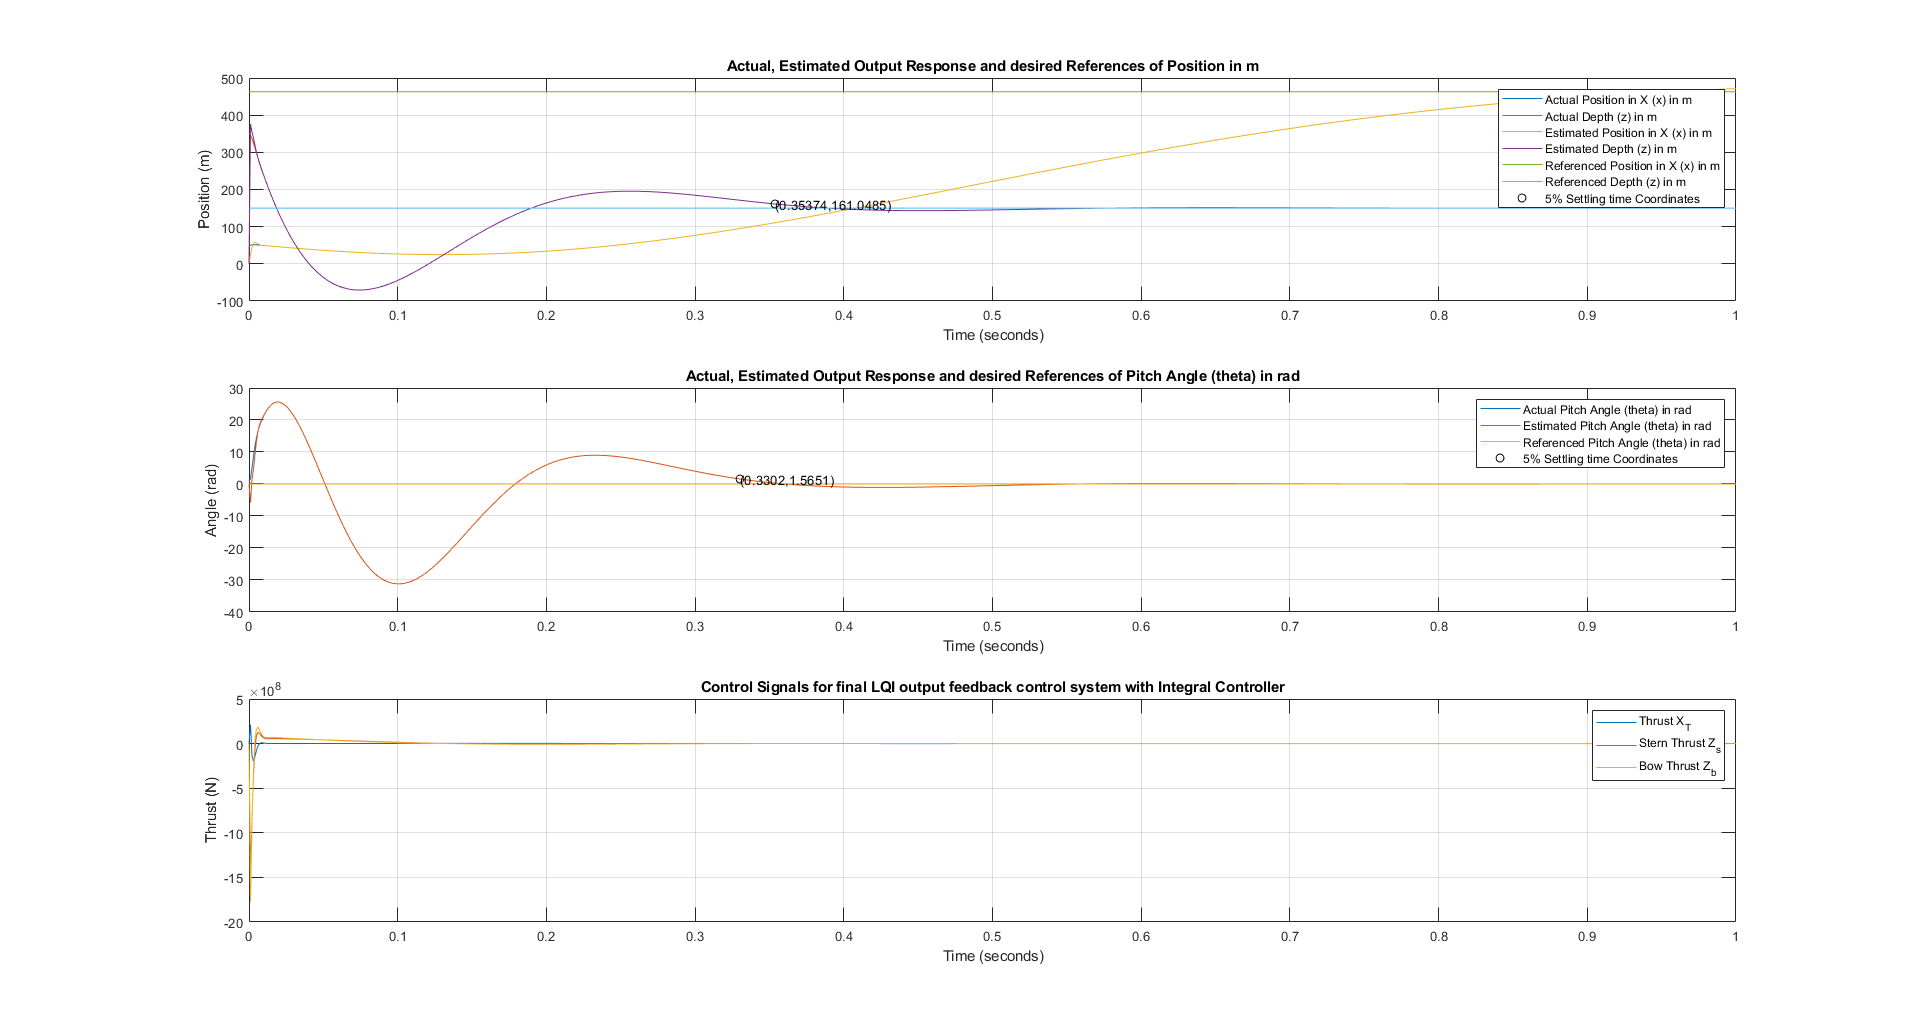

% Plotting
figure()
% Construct the 1st plot of just Positions in m
subplot(3,1,1)
plot(t_final_lqi,Y_final_actual(:,1));
grid on
hold on
plot(t_final_lqi,Y_final_actual(:,2));
plot(t_final_lqi,Y_final_estimated(:,1));
plot(t_final_lqi,Y_final_estimated(:,2));
plot(t_final_lqi,refrence_input(:,1));
plot(t_final_lqi,refrence_input(:,2));
title('Actual, Estimated Output Response and desired References of Position in m');
xlabel('Time (seconds)');
ylabel('Position (m)');
% xlim([0 3750]);

plot(SimulationStuff1_final_lqi.SettlingTime, X_at_SettlingTime_final_lqi,'kO');
text(SimulationStuff1_final_lqi.SettlingTime, X_at_SettlingTime_final_lqi,['(' num2str(SimulationStuff1_final_lqi.SettlingTime) ',' num2str(X_at_SettlingTime_final_lqi) ')']);

plot(SimulationStuff2_final_lqi.SettlingTime, Depth_at_SettlingTime_final_lqi,'kO');
text(SimulationStuff2_final_lqi.SettlingTime, Depth_at_SettlingTime_final_lqi,['(' num2str(SimulationStuff2_final_lqi.SettlingTime) ',' num2str(Depth_at_SettlingTime_final_lqi) ')']);
legend('Actual Position in X (x) in m', 'Actual Depth (z) in m',...
       'Estimated Position in X (x) in m', 'Estimated Depth (z) in m',...
       'Referenced Position in X (x) in m', 'Referenced Depth (z) in m',...    
       '5% Settling time Coordinates');
hold off

% Construct the 2nd Plot of just Pitch Angle in rad
subplot(3,1,2)
plot(t_final_lqi,Y_final_actual(:,3));
hold on
grid on
plot(t_final_lqi,Y_final_estimated(:,3));
plot(t_final_lqi,refrence_input(:,3));
title('Actual, Estimated Output Response and desired References of Pitch Angle (theta) in rad');
xlabel('Time (seconds)')
ylabel('Angle (rad)');

plot(SimulationStuff3_final_lqi.SettlingTime, PitchAngle_at_SettlingTime_final_lqi,'kO');
text(SimulationStuff3_final_lqi.SettlingTime, PitchAngle_at_SettlingTime_final_lqi,['(' num2str(SimulationStuff3_final_lqi.SettlingTime) ',' num2str(PitchAngle_at_SettlingTime_final_lqi) ')']);
legend('Actual Pitch Angle (theta) in rad', 'Estimated Pitch Angle (theta) in rad',...    
       'Referenced Pitch Angle (theta) in rad', '5% Settling time Coordinates');
% xlim([0 3750]);
% ylim([-0.3 1]);
hold off

% Plotting the Control Signals
subplot(3, 1, 3)
plot(t_final_lqi, CtrlThrust_final_lqi(:,1))
hold on
plot(t_final_lqi, CtrlThrust_final_lqi(:,2))
plot(t_final_lqi, CtrlThrust_final_lqi(:,3))
hold off
grid on
legend('Thrust X_T', 'Stern Thrust Z_s', 'Bow Thrust Z_b');
xlabel('Time (seconds)');
ylabel('Thrust (N)');
title('Control Signals for final LQI output feedback control system with Integral Controller');
% xlim([0 3750]);
% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

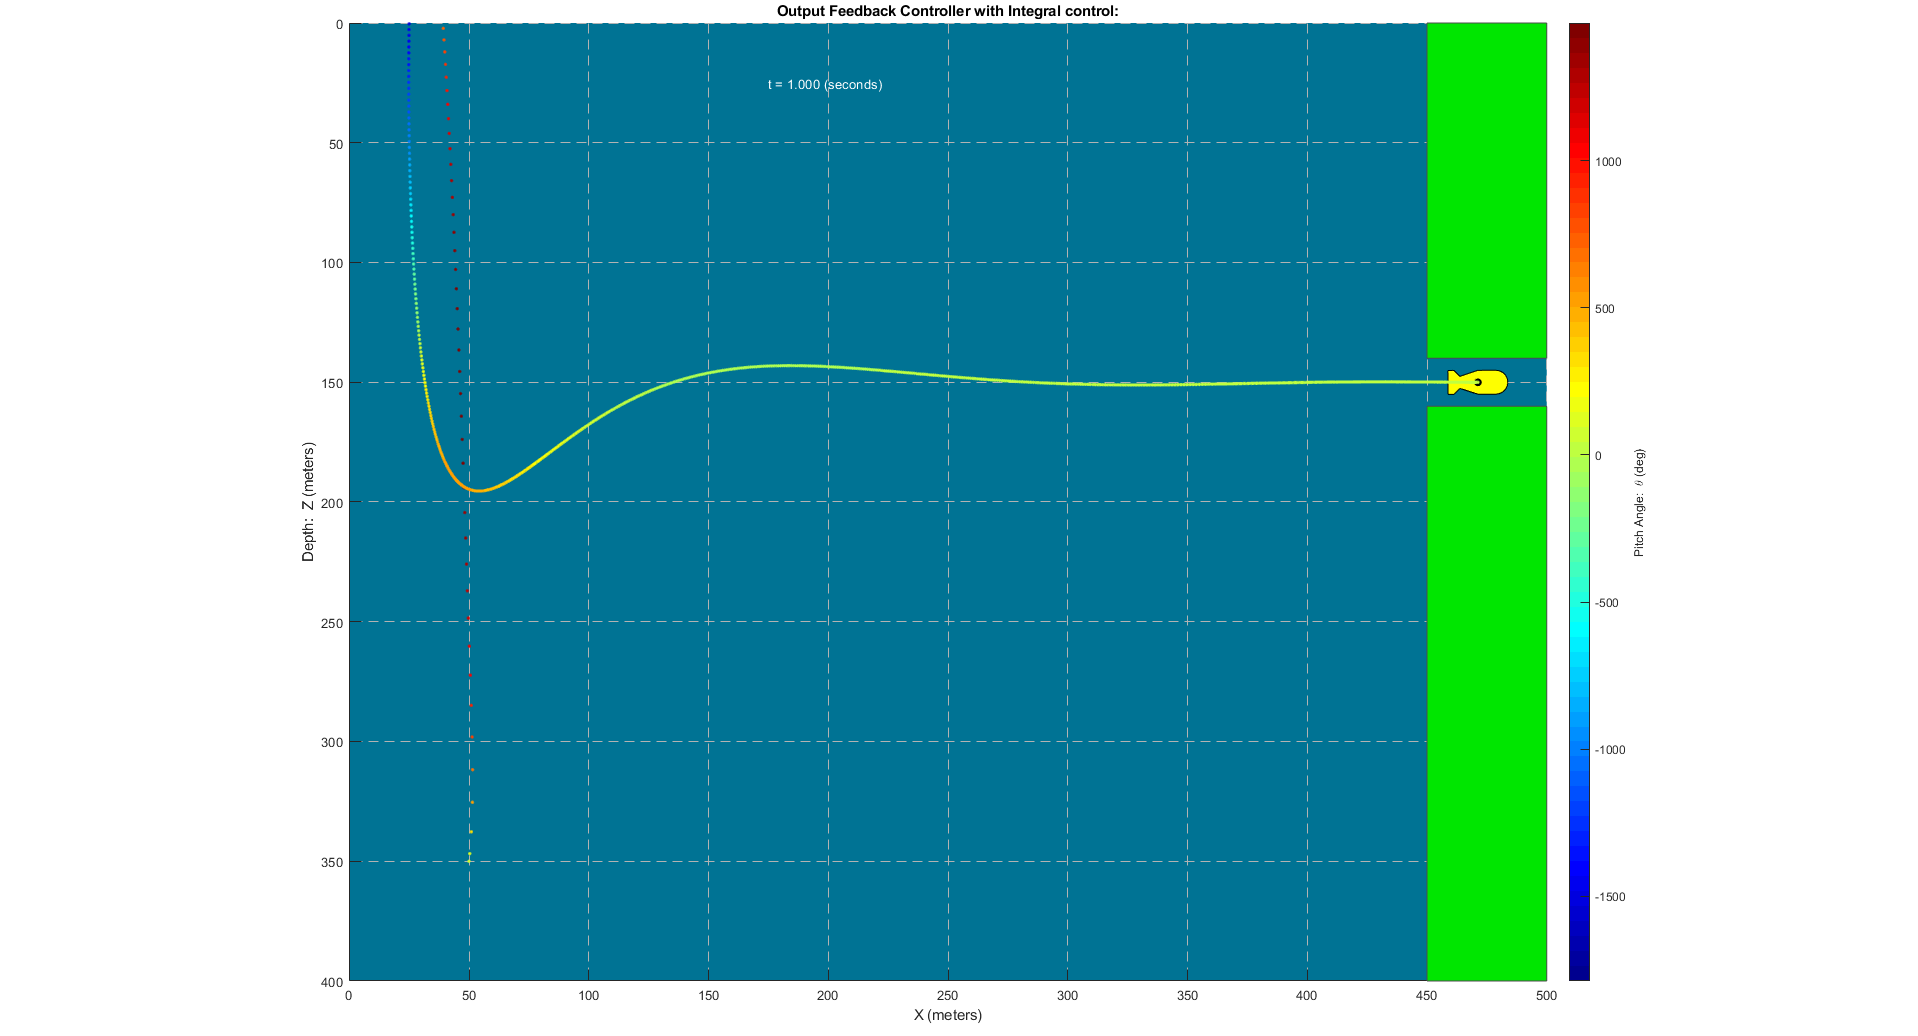


% animate_auv(t,x,z,theta,savemovie);
animate_auv(t_final_lqi,Y_final_actual(:,1),Y_final_actual(:,2),Y_final_actual(:,3), 0);
title('Output Feedback Controller with Integral control:');
% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

# Extra Credit

## **Performance requirements:**

- No requirement or limit on control signal but it should converge to 0 eventually.

- All estimated outputs should converge to corresponding actual outputs.

- All actual outputs should converge to the desired references with 0 steady state error and within the trequired time limit

- AUV must completely enter the tunnel without contacting the barrier

- AUV must completely enter the tunnel with a tunnel height of 10.5m, which means that the AUV only have a 0.5m clearence since the AUV is 10m in height

- Total Simulation time should be less than 2 sec i.e. the AUV should completely enter the tunnel in < 2 sec

- 5% Settling time of all three outputs must be less than 1 second.

## **Requirements Passed:**

- 5% Settling times: X - 0.92 seconds, Z - 0.35 seconds , $\theta$ - 0.33 seconds

- All the estimated outputs converge to actual outputs

- All actual outputs converge to the desired references with 0 steady state error within 

- Time Taken for AUV to Enter the 10.5m Tunnel/Total Simulation Time: 0.7 seconds

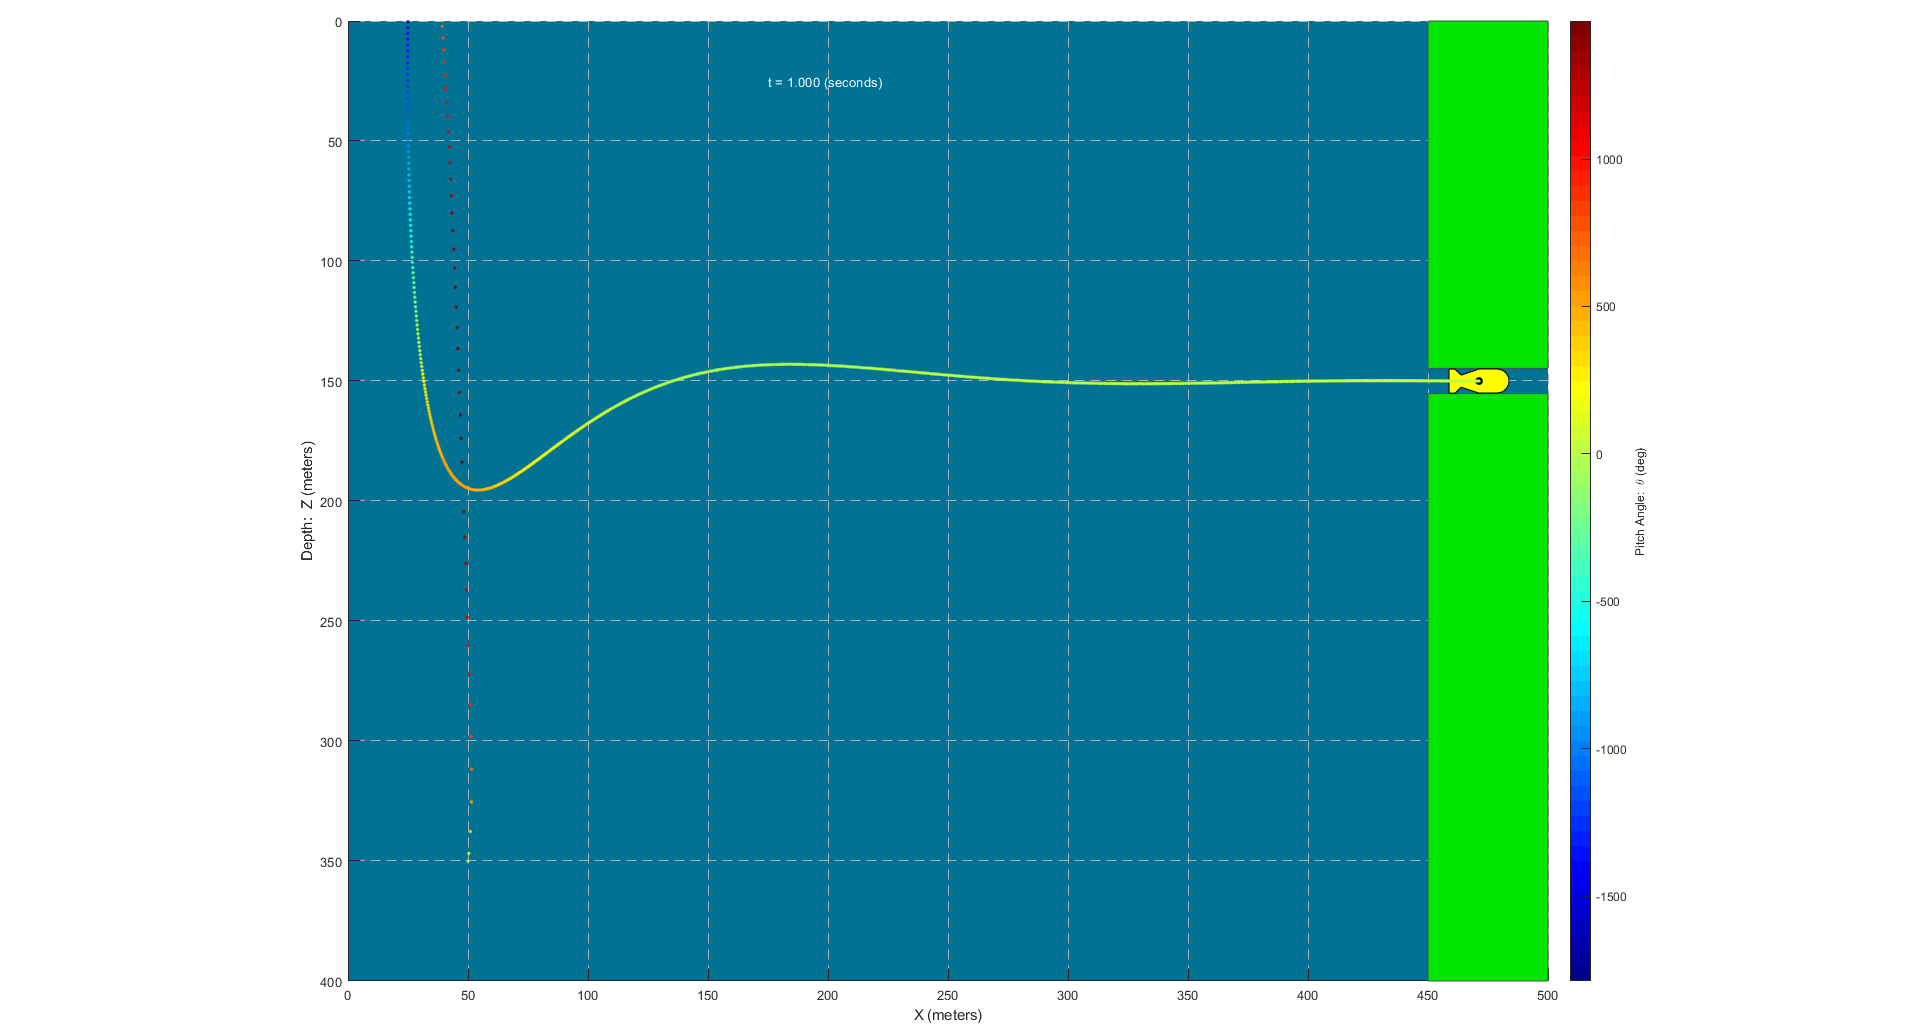

% animate_auv(t,x,z,theta,savemovie);
animate_auv(t_final_lqi,Y_final_actual(:,1),Y_final_actual(:,2),Y_final_actual(:,3), 0, 10.5);
% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);